# Actividad 5.1: Control de Posición

**Paola Rojas Domínguez A01737136**

Este código implementa un modelo cinemático de un robot móvil diferencial que se desplaza desde una posición inicial hacia un punto objetivo fijo. Se emplea un controlador basado en la inversión del Jacobiano para calcular las velocidades lineal y angular necesarias en cada instante. Posteriormente, se actualiza la posición y orientación del robot utilizando el método de Euler. Además, el código incluye una visualización 3D del movimiento y gráficas del comportamiento de las velocidades y el error de posición durante la simulación.

## Inicialización

Se inicia limpiando la consola y la memoria para evitar conflictos de datos anteriores.

clear all
close all
clc

## Tiempo

Se definen los parámetros temporales del experimento: duración total (`tf`), intervalo de muestreo (`ts`), y se genera el vector de tiempo (`t`) con su longitud total (`N`), que define la cantidad de pasos de simulación.

tf=15;             % Tiempo de simulación en segundos (s)
ts=0.1;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras

## **Lista de puntos deseados**

Se genera una matriz que representa los puntos deseados para generar el control de posición del robot tipo diferencial

puntos_deseados = [1,   2;   % a) (1, 2)
                   3,   7;   % b) (3, 7)
                   6,   0;   % c) (6, 0)
                  -4,   5;   % d) (-4, 5)
                  -6,   0;   % e) (-6, 0)
                  -1,   0;   % f) (-1, 0)
                  -7,  -7;   % g) (-7, -7)
                  -2,  -4;   % h) (-2, -4)
                  -0.5,-0.5; % i) (- 0.5, -0.5)
                   1,  -3;   % j) (1, -3)
                   3,  -5;   % k) (3, -5)
                   8,   0;   % l) (8, 0)
                   0,  -3;   % m) (0, -3)
                   0,   9;   % n) (0, 9)
                   0,  -1;   % o) (0, -1)
                  -5,  -10;  % p) (-5, -10)
                   7,  -7;   % q) (7, -7)
                   3,  -1;   % r) (3, -1)
                  -10, -10;  % s) (- 10, -10)
                   10, 9];   % t) (10, 9)

## Bucle de iteración 1: K = [10 0; 0 10];

sizeScreen = get(0,'ScreenSize');
scale = 4;

for i = 1:size(puntos_deseados,1)   

### Posición deseada

Se define el objetivo fijo al que debe llegar el robot (`hxd`, `hyd`).

    hxd = puntos_deseados(i,1);
    hyd = puntos_deseados(i,2);

### Condiciones iniciales

Se establecen las condiciones iniciales del robot: su posición en el plano (x, y) y su orientación (`phi`) medida en radianes. En este caso, el robot comienza en el origen apuntando hacia

    x1(1) = 0;
    y1(1) = 0;
    phi(1) = pi/2;

Inicialmente, la posición del punto de control del robot coincide con su posición actual (`hx`, `hy`).

    hx(1)=x1(1);
    hy(1)=y1(1);

    % Inicialización
    v = zeros(1,N); w = zeros(1,N); Error = zeros(1,N);

### Control, bucle de simulación

Se ejecuta un bucle a lo largo del tiempo de simulación. En cada iteración se calcula el error en las coordenadas X e Y entre el objetivo y la posición actual. Luego, se calcula la magnitud total del error. 

    for k = 1:N 
        hxe = hxd - hx(k); hye = hyd - hy(k);
        he = [hxe; hye];
        Error(k) = norm(he);

 Se construye la matriz Jacobiana que transforma errores en el marco global a comandos de movimiento en el marco del robot.

        J = [cos(phi(k)) -sin(phi(k)); sin(phi(k)) cos(phi(k))];

También se establece la matriz de ganancias proporcional para el controlador. Determina la agresividad con la que se corrige el error.

        K = [10 0; 0 10];

Se aplica una ley de control basada en la pseudoinversa del Jacobiano para obtener las velocidades lineal (`v`) y angular (`w`) que minimizan el error.

        qpRef = pinv(J) * K * he;
        v(k) = qpRef(1);
        w(k) = qpRef(2);

#### Aplicación del control al modelo cinemático

Se integran las velocidades para actualizar la orientación (`phi`) y posición (`x1`, `y1`) del robot utilizando el método de Euler. La posición del punto de control (`hx`, `hy`) se mantiene coincidente con el robot.

        phi(k+1) = phi(k) + w(k)*ts;
        xp1 = v(k)*cos(phi(k));
        yp1 = v(k)*sin(phi(k));
        x1(k+1) = x1(k) + xp1*ts;
        y1(k+1) = y1(k) + yp1*ts;
        hx(k+1) = x1(k+1);
        hy(k+1) = y1(k+1);
    end

### Simulacion virtual 3D 

Tras la simulación cinemática, se configura un entorno 3D para visualizar el comportamiento del robot. Se crea una figura de tamaño completo con fondo blanco, se ajustan los ejes con proporciones iguales y se establecen etiquetas y cuadrículas para facilitar la lectura del entorno. Se coloca una luz en la escena y se orienta la vista para una mejor perspectiva. Los límites de visualización se establecen para acomodar el espacio que recorrerá el robot.

#### a) Configuracion de escena

    scene = figure('Name',['Animación punto ' char(96+i) ' → (' num2str(hxd) ',' num2str(hyd) ')']);
    set(scene, 'Color','white', 'position', sizeScreen);
    set(gca,'FontWeight','bold') ;
    sizeScreen=get(0,'ScreenSize');
    camlight('headlight');
    axis equal;
    grid on;
    box on;
    xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
    view([-0.1 35]);

    % Obtener coordenadas del punto deseado
    px = puntos_deseados(i,1);
    py = puntos_deseados(i,2);
    
    % Obtener el mayor valor absoluto entre x y y
    var = max([abs(px), abs(py), 1]); % Asegura al menos 1 metro de visibilidad
    lim = 1.5*var;
    
    % Establecer límites simétricos en x e y
    axis([-lim lim -lim lim 0 1]);

#### **b) Graficar robots en la posicion inicial**

    MobileRobot_5;
    H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;

#### **c) Graficar trayectorias**

    H2 = plot3(hx(1), hy(1), 0, 'Color', [1 0.4 0.7], 'LineWidth', 2);
    H3 = plot3(hxd, hyd, 0, 'co', 'LineWidth', 2); % Punto deseado
    H4 = plot3(hx(1), hy(1), 0, 'go', 'LineWidth', 2); % Punto inicial

#### **d) Bucle de simulacion de movimiento del robot**

    disp(['Inciso ' char(96+i) ')']);
    step = 1;
    for k = 1:step:N
        delete(H1);
        delete(H2);
        H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
        H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'Color', [1 0.4 0.7], 'LineWidth', 2);
        pause(ts);
    end

### Gráficas

Finalmente, se generan tres gráficas: velocidad lineal (`v`), velocidad angular (`w`), y el error de posición acumulado en el tiempo. Estas permiten analizar el desempeño del controlador.

Inciso a)


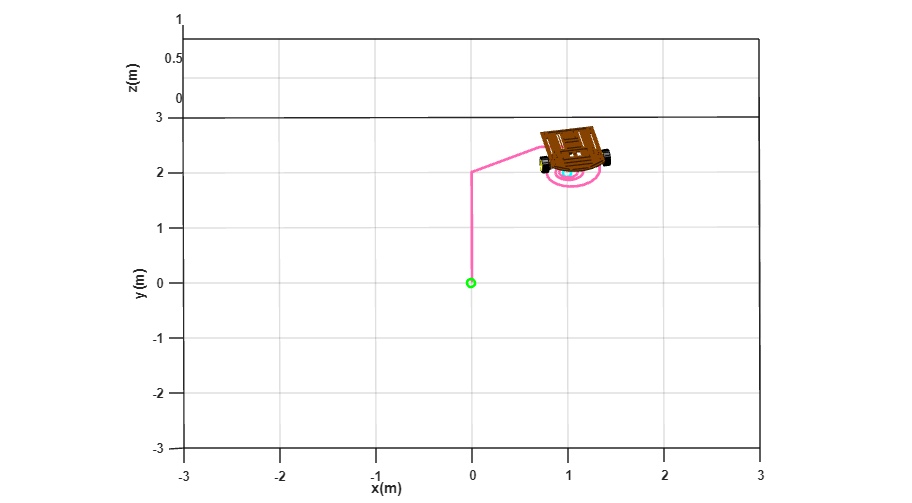

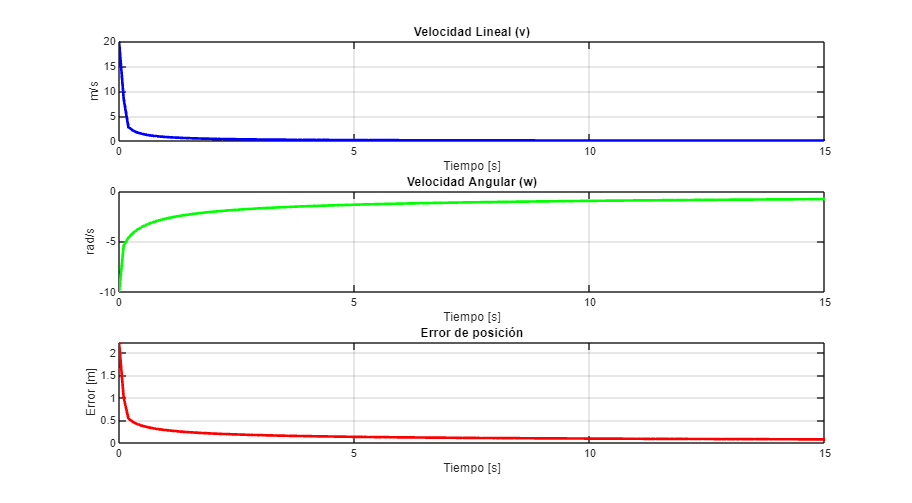

Inciso b)


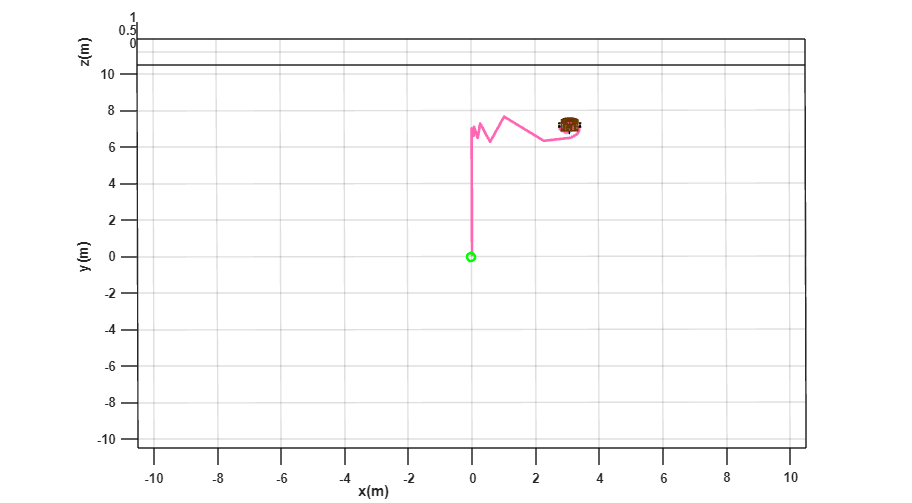

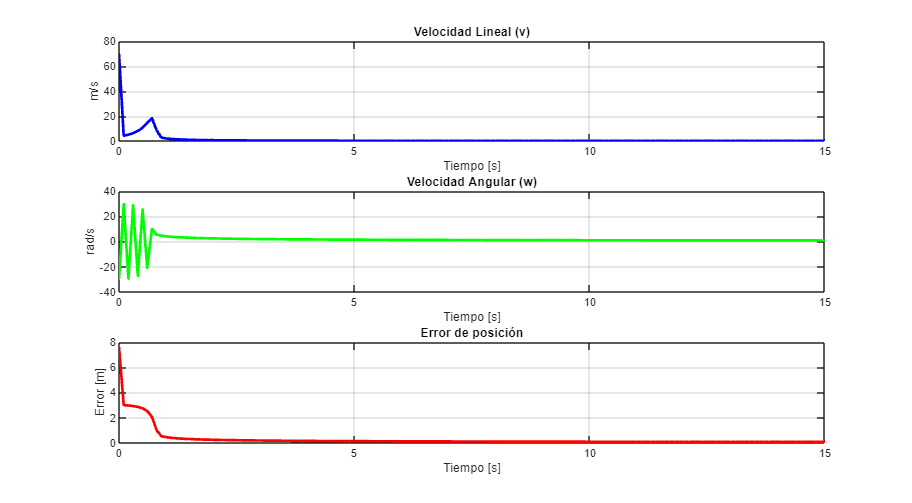

Inciso c)


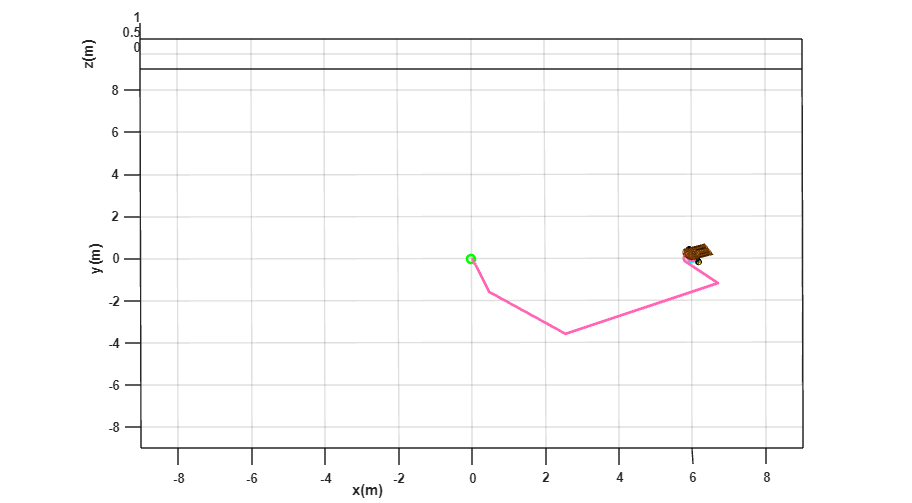

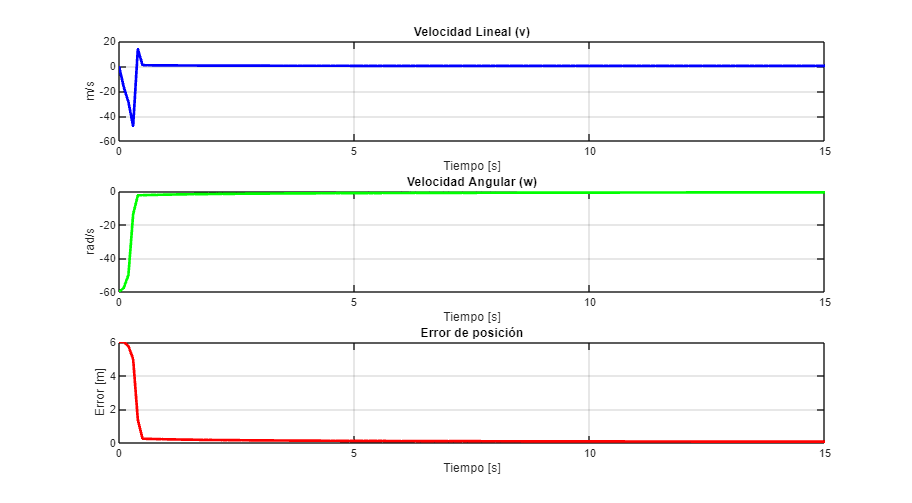

Inciso d)


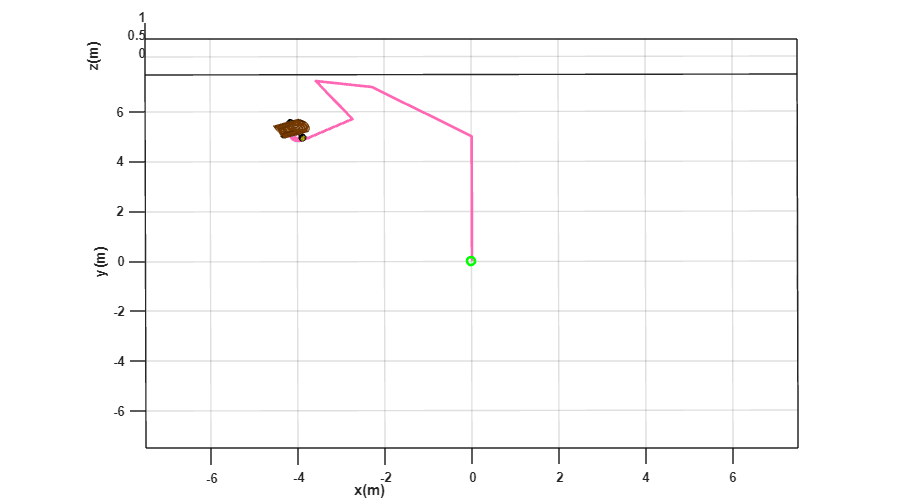

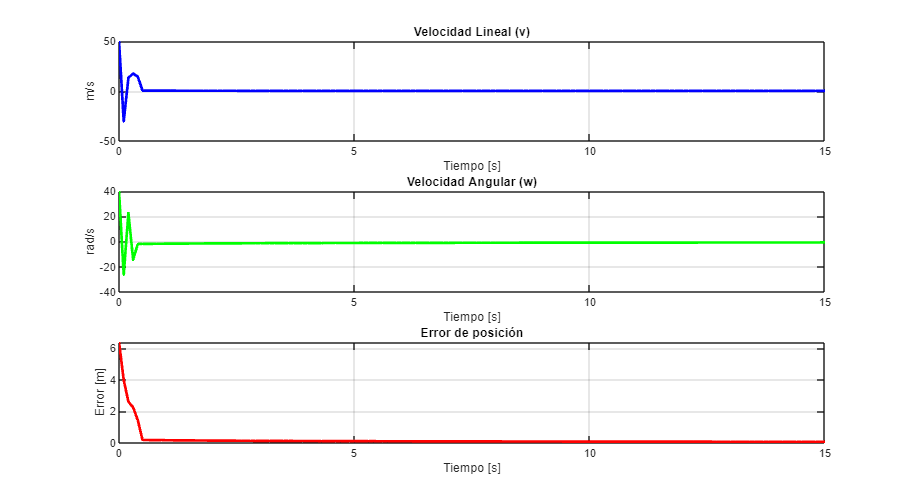

Inciso e)


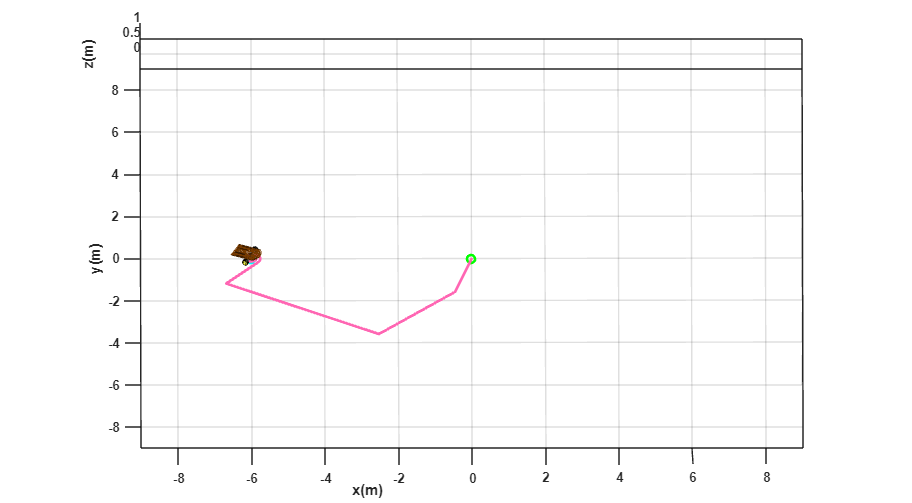

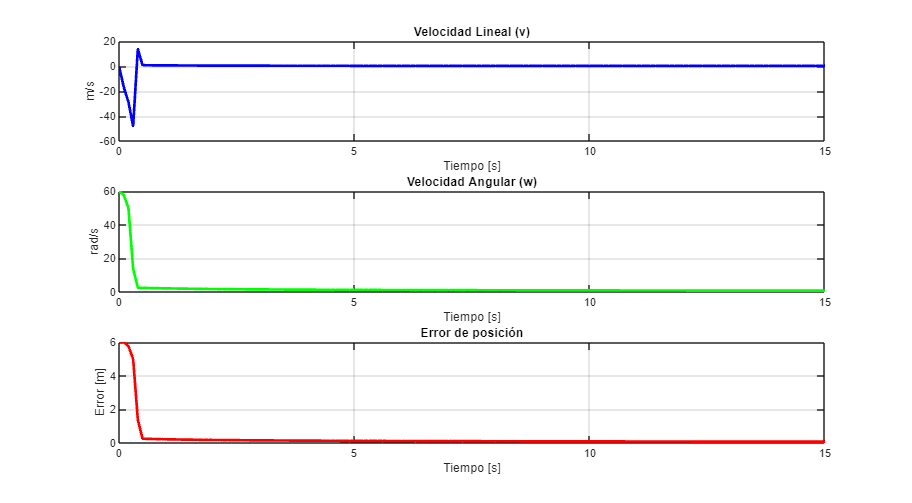

Inciso f)


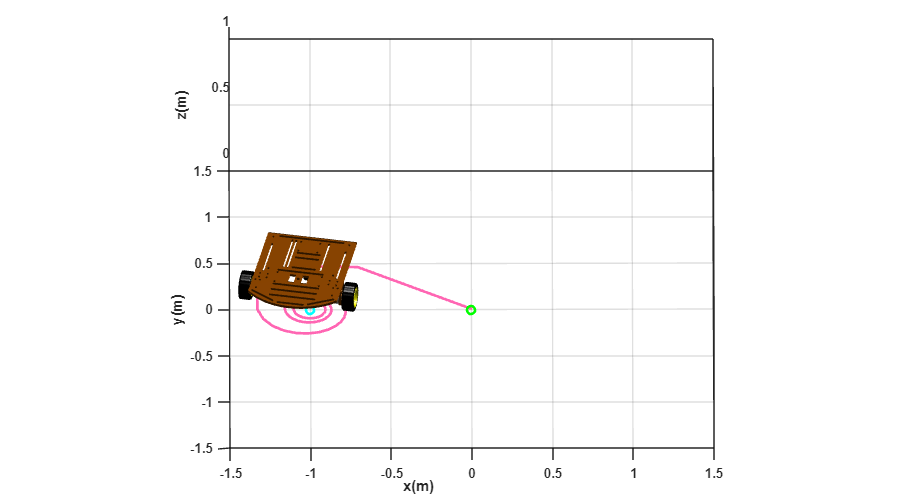

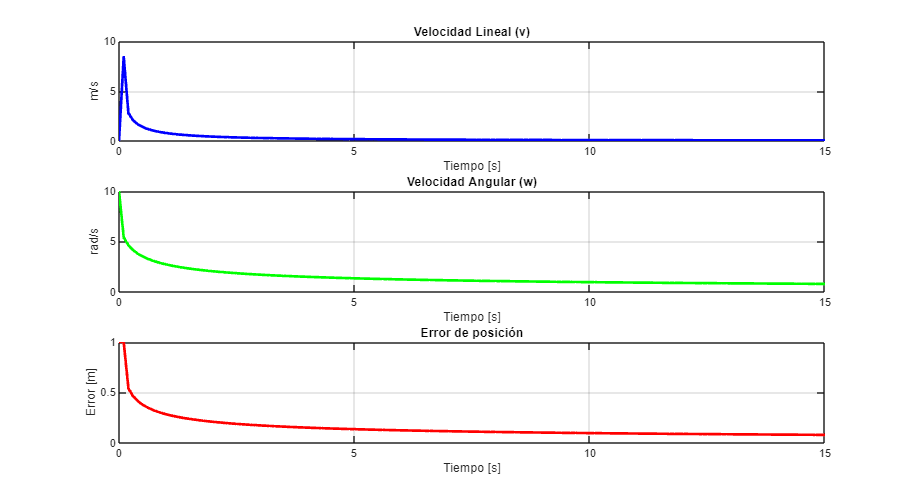

Inciso g)


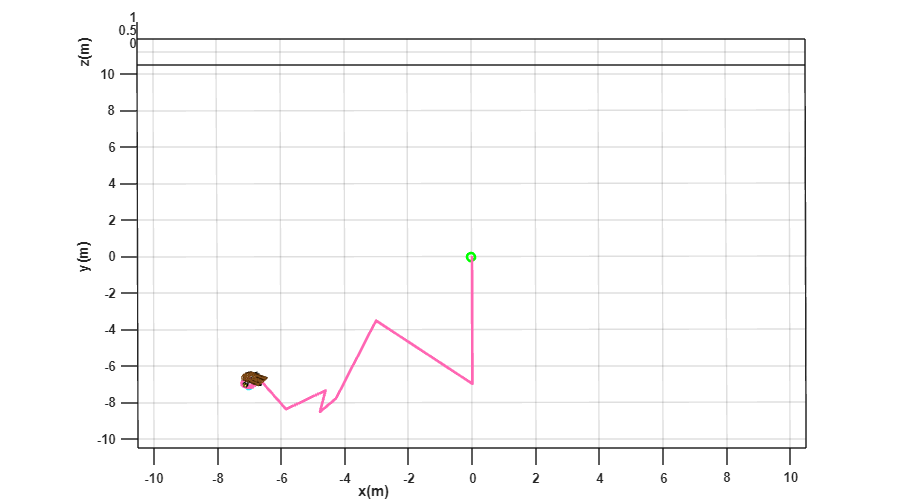

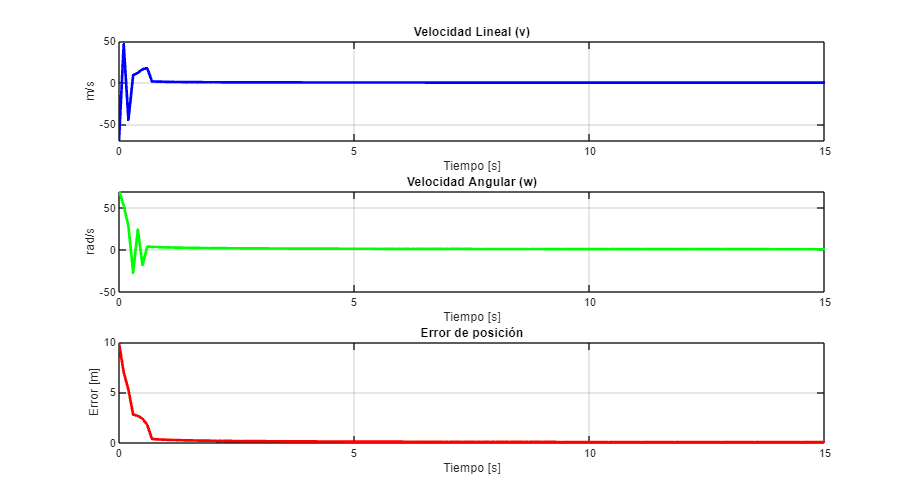

Inciso h)


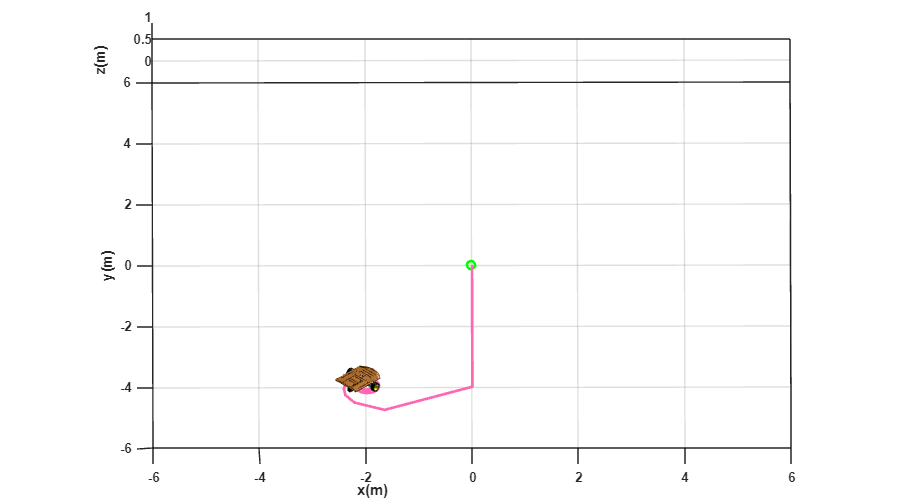

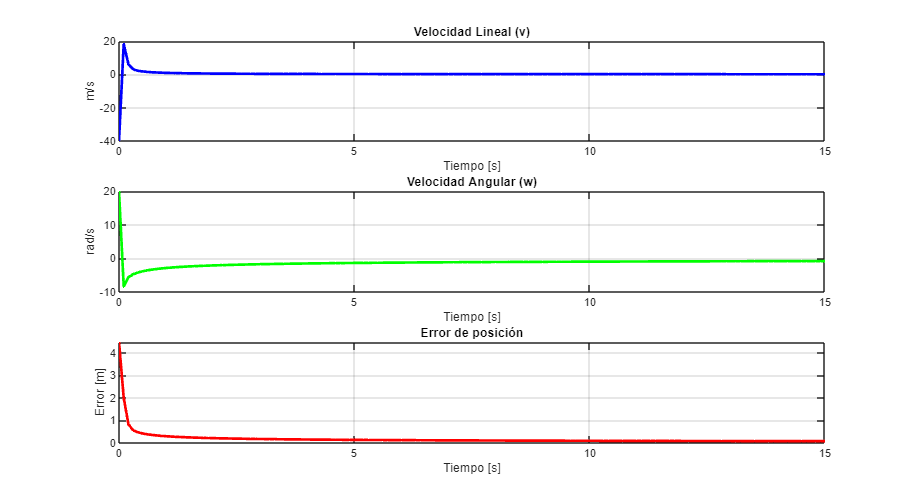

Inciso i)


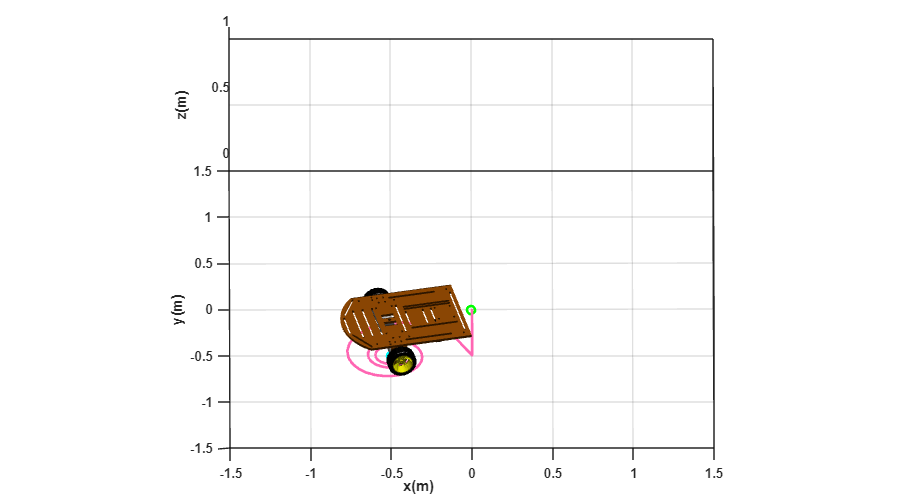

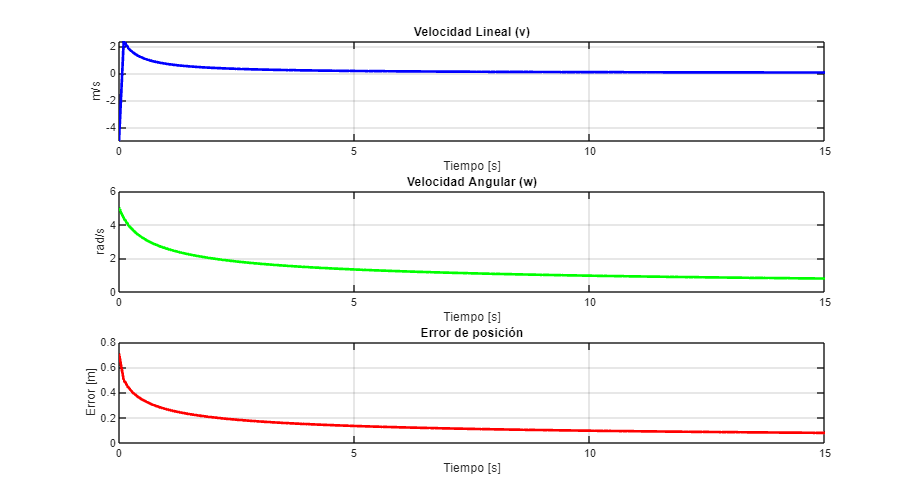

Inciso j)


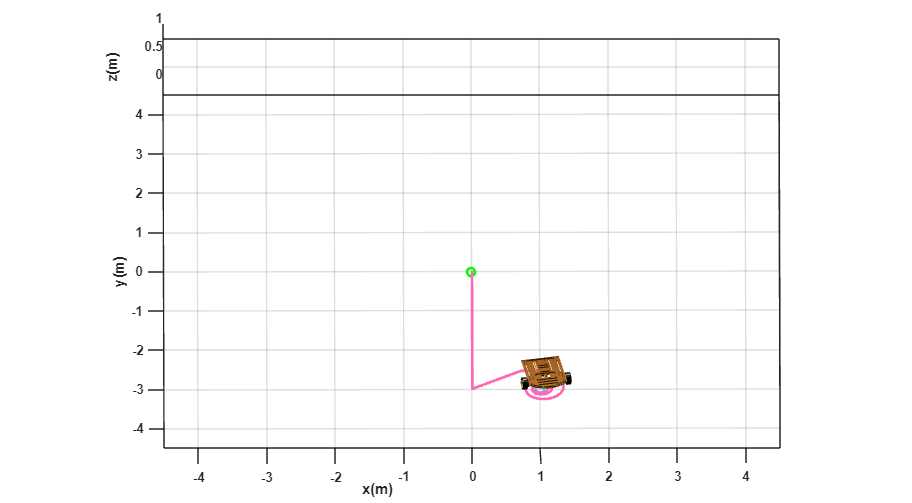

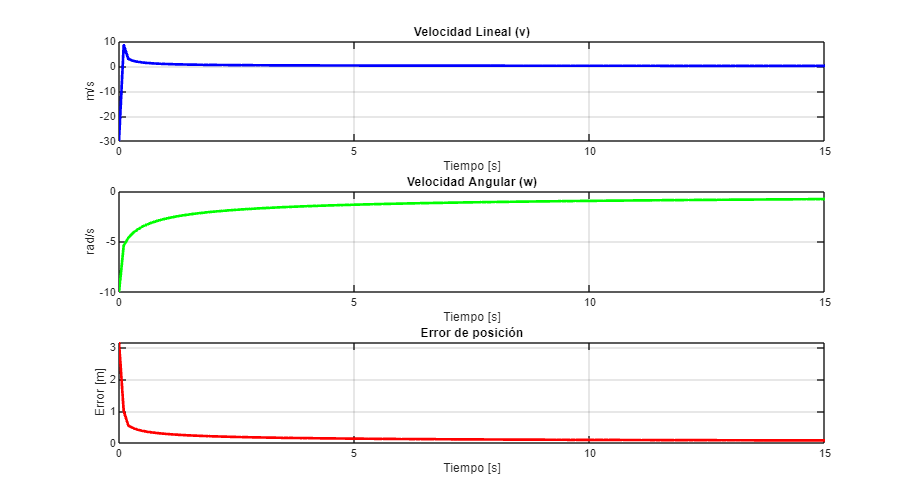

Inciso k)


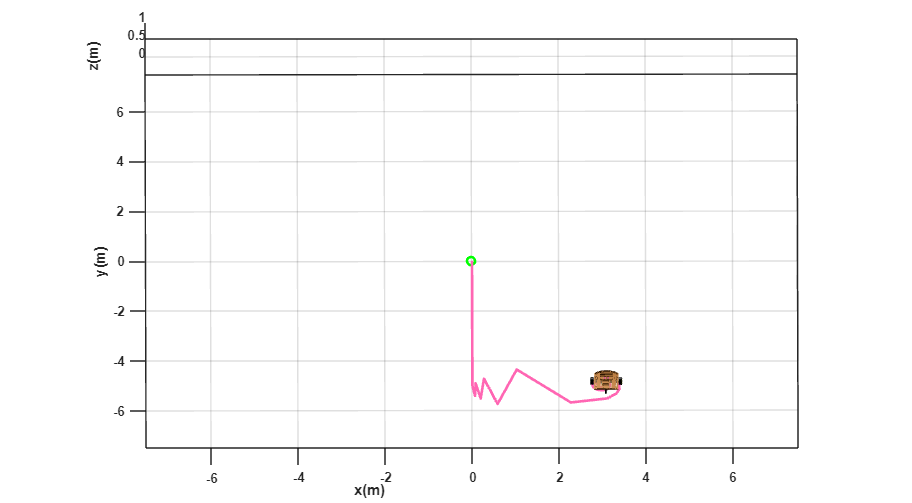

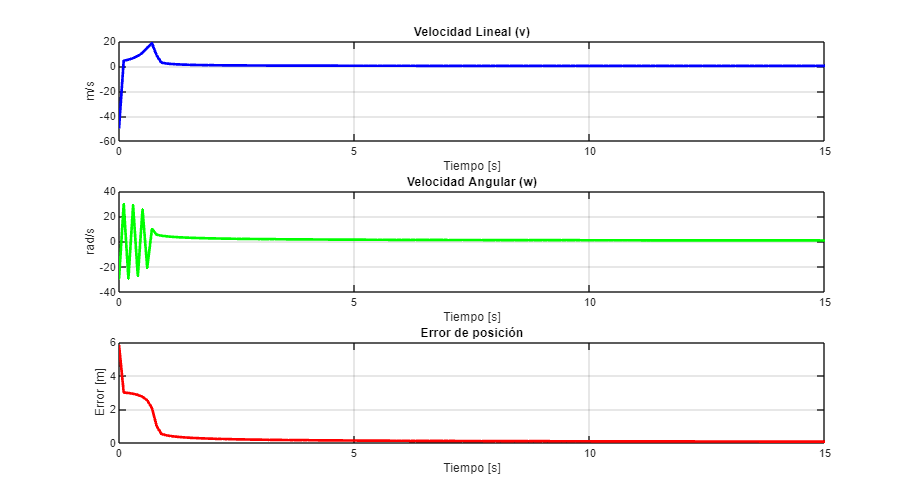

Inciso l)


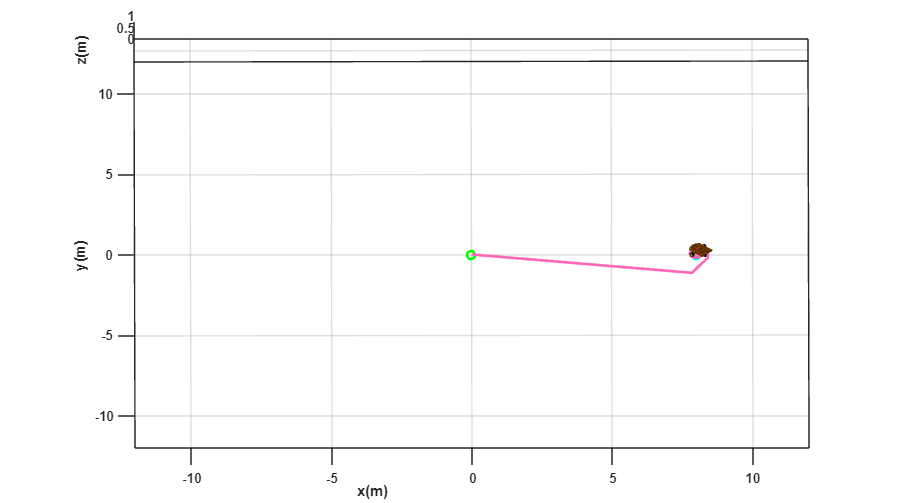

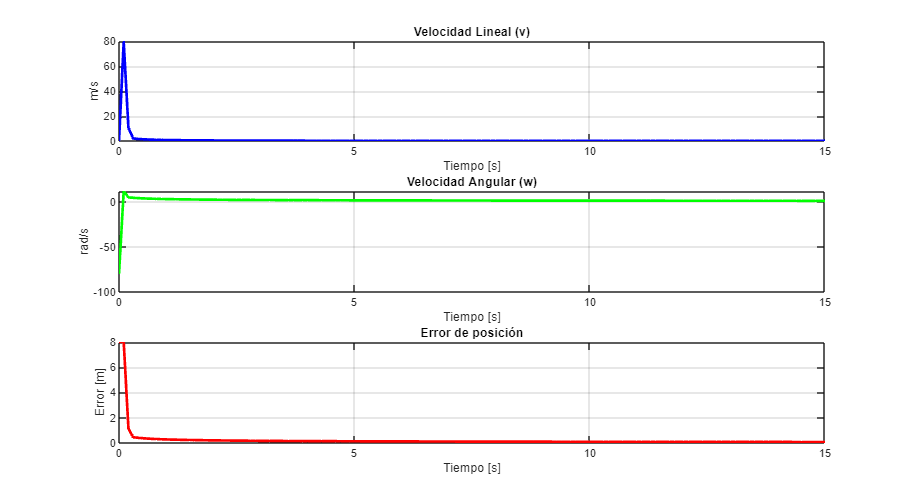

Inciso m)


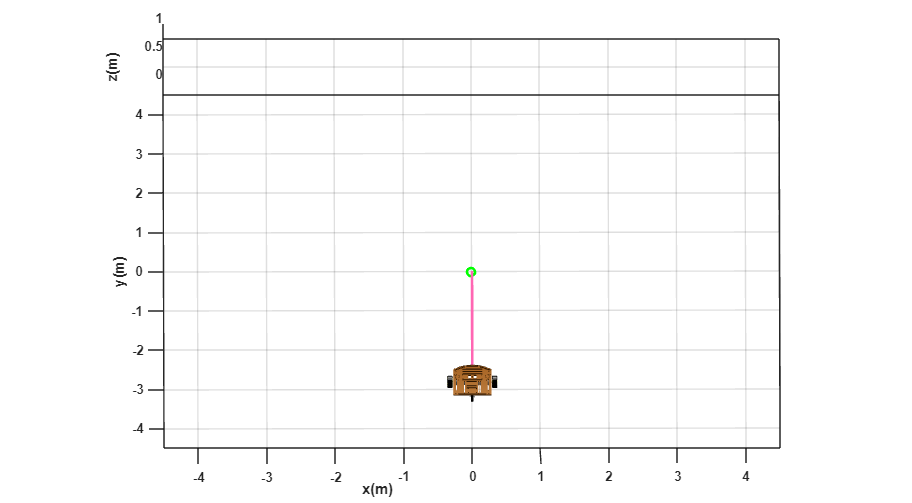

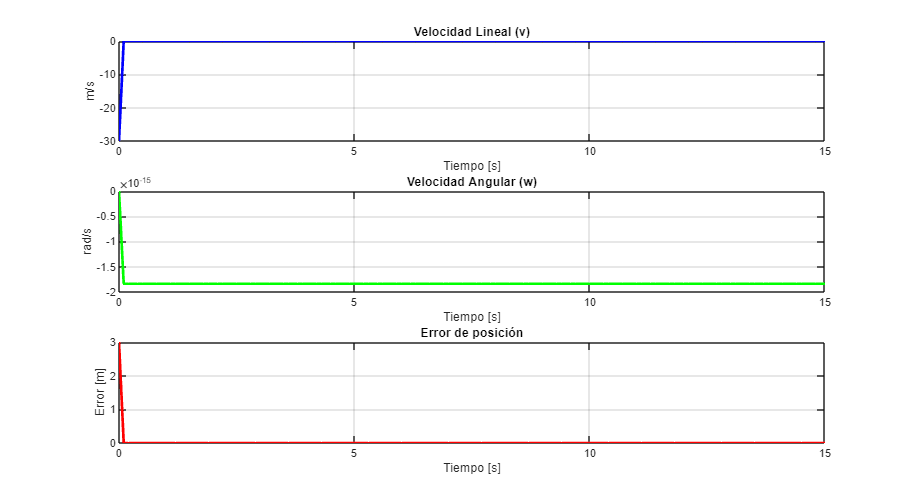

Inciso n)


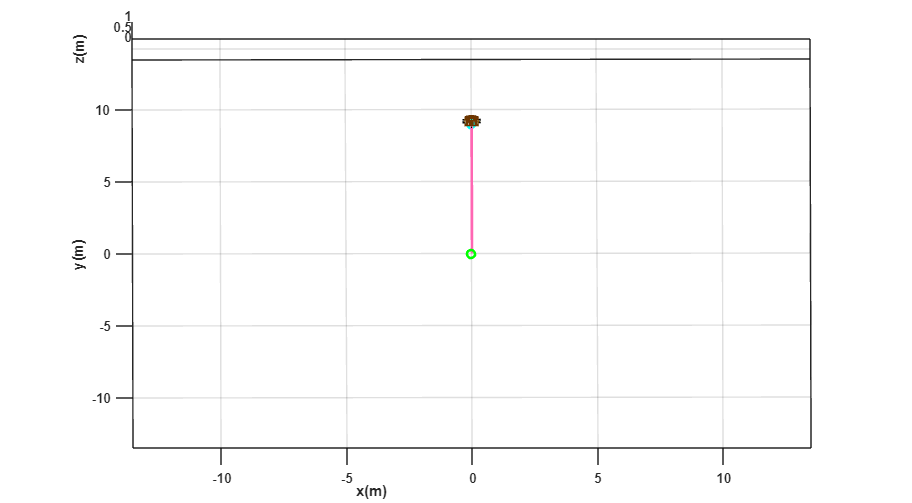

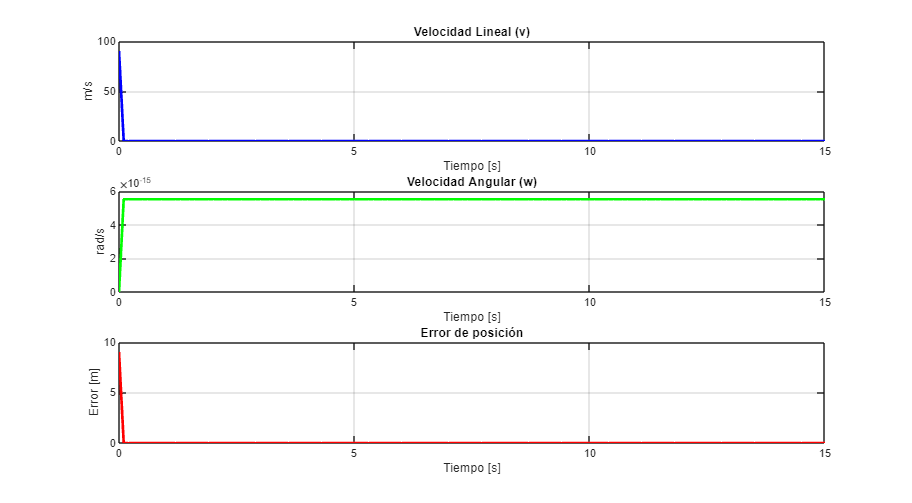

Inciso o)


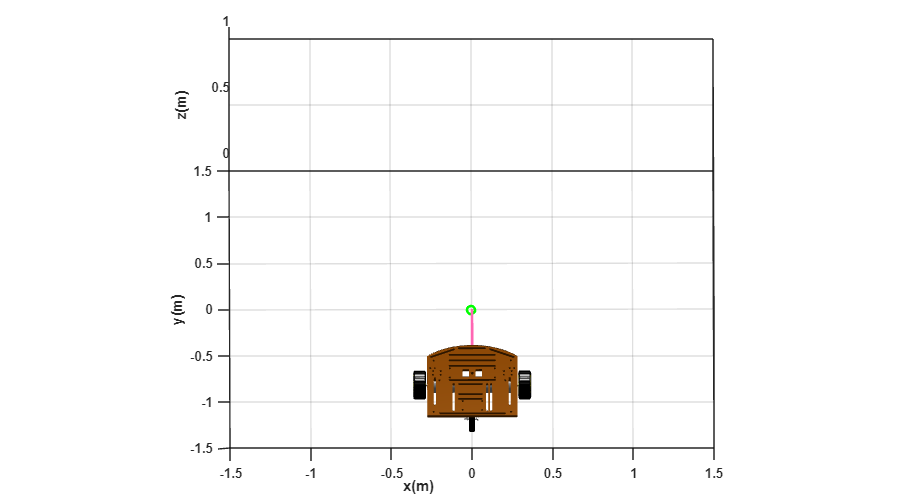

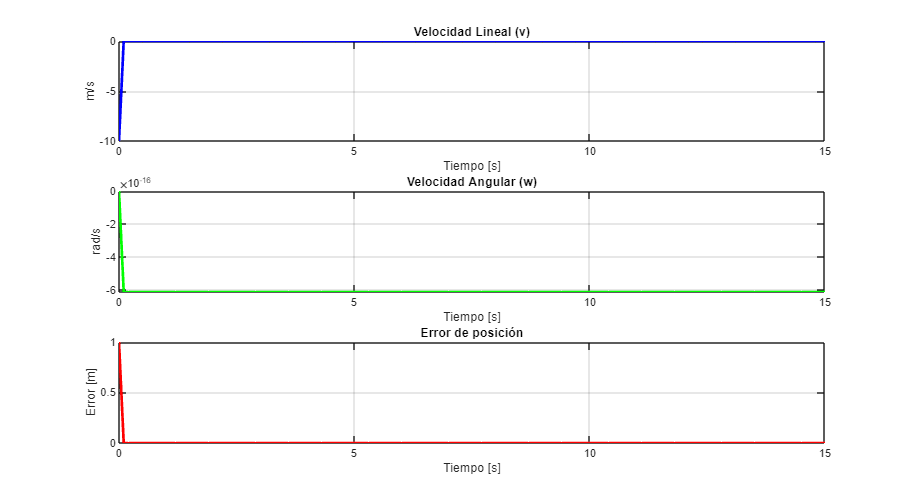

Inciso p)


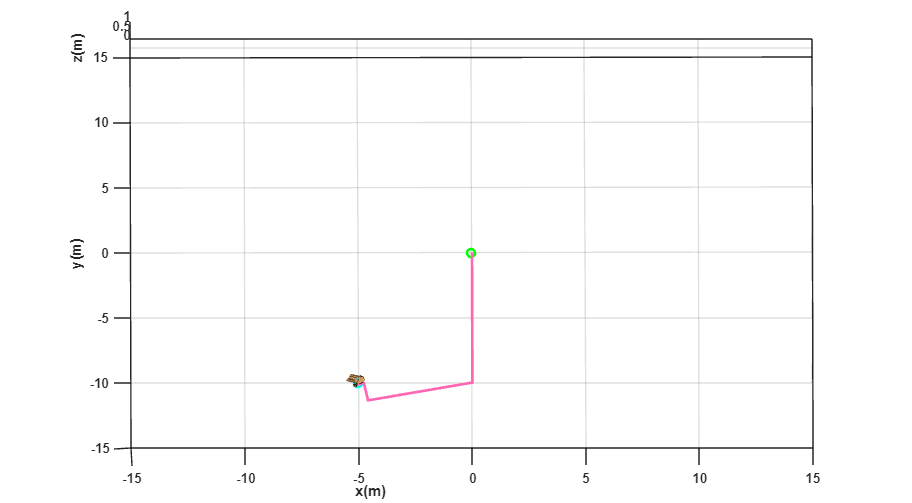

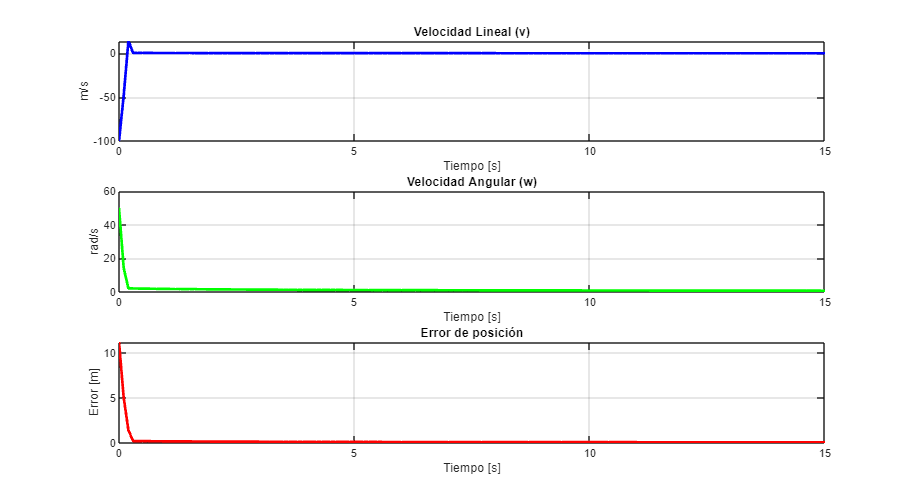

Inciso q)


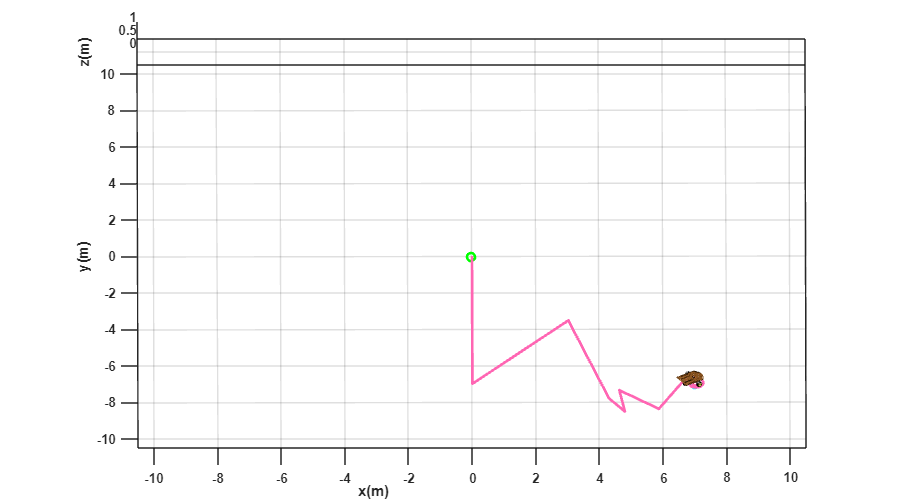

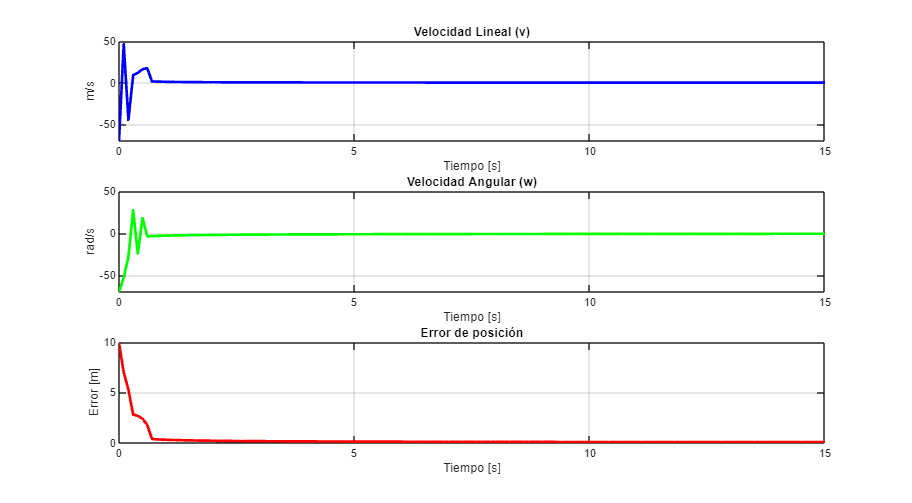

Inciso r)


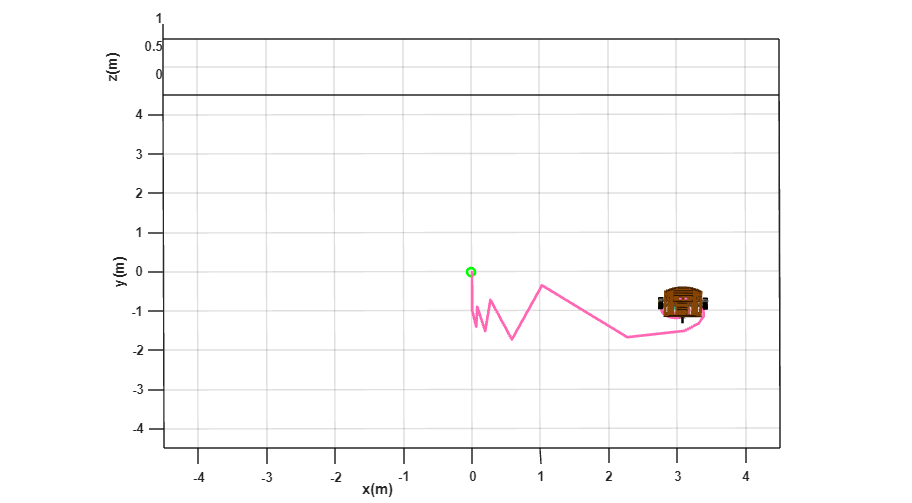

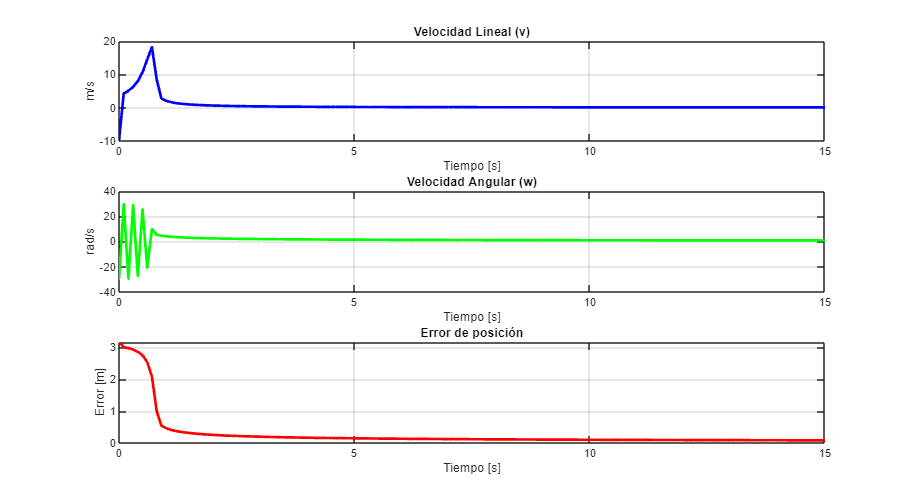

Inciso s)


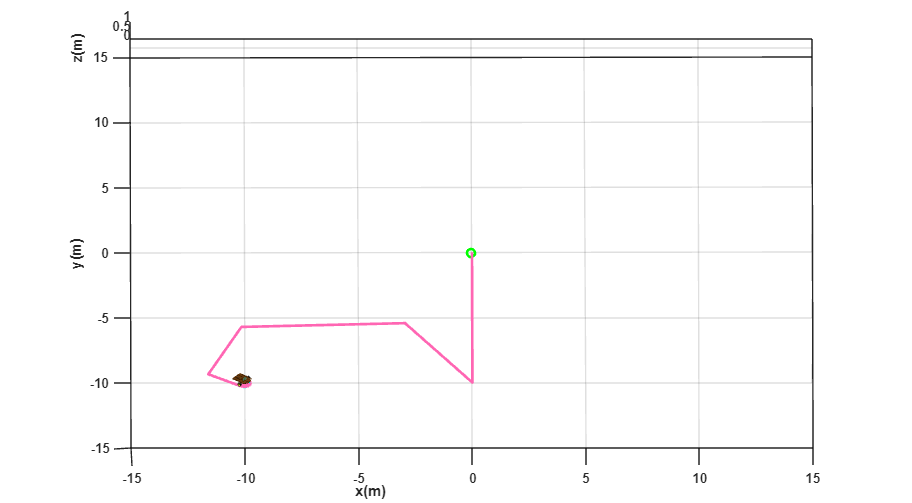

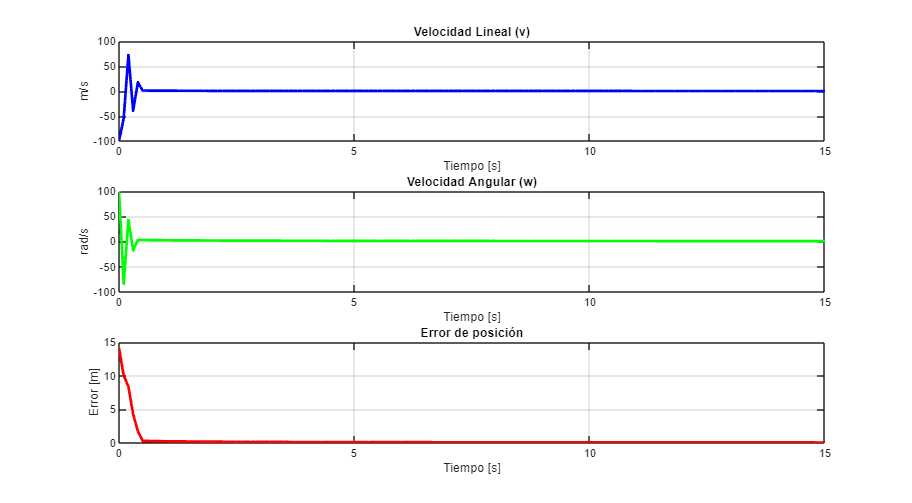

Inciso t)


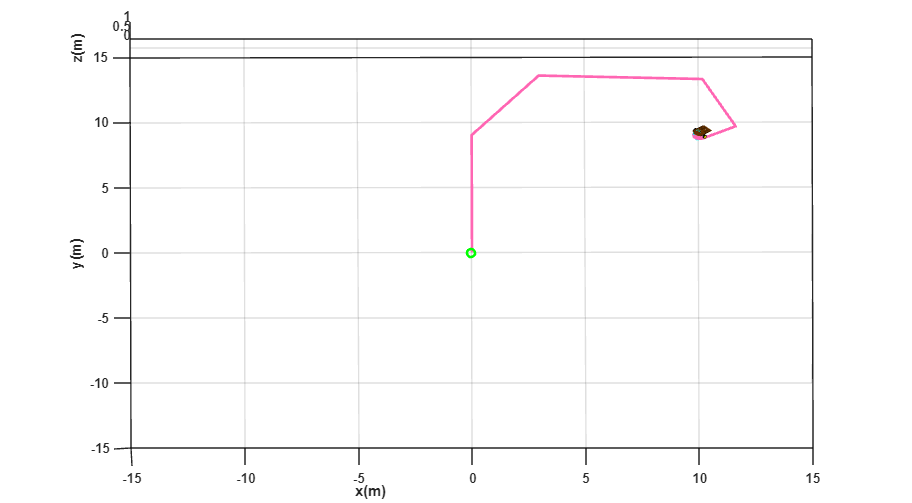

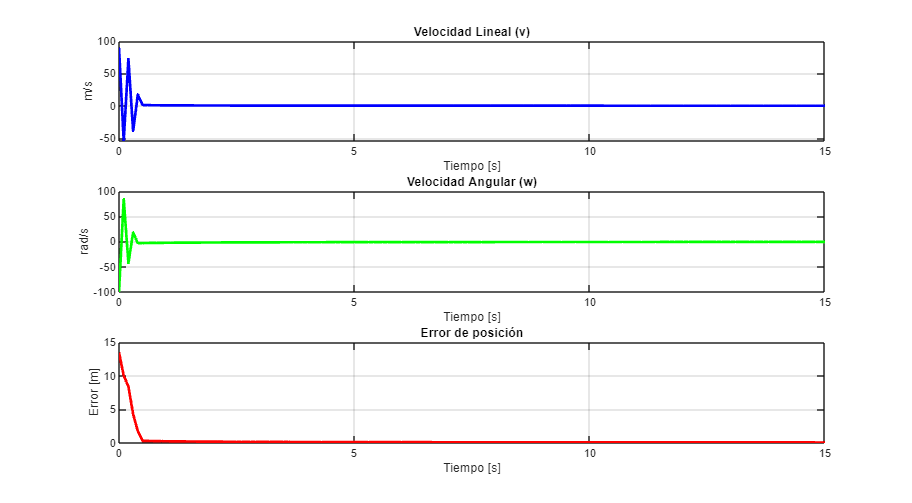

    graph = figure('Name',['Gráficas punto ' char(96+i)], 'position', sizeScreen);

    subplot(311)
    plot(t, v, 'b', 'LineWidth', 2); grid on;
    xlabel('Tiempo [s]'); ylabel('m/s');
    title('Velocidad Lineal (v)');

    subplot(312)
    plot(t, w, 'g', 'LineWidth', 2); grid on;
    xlabel('Tiempo [s]'); ylabel('rad/s');
    title('Velocidad Angular (w)');

    subplot(313)
    plot(t, Error, 'r', 'LineWidth', 2); grid on;
    xlabel('Tiempo [s]'); ylabel('Error [m]');
    title('Error de posición');
    
    pause(1); % Espera entre puntos
end

## Bucle de iteración 2: K = [5 0; 0 5];

sizeScreen = get(0,'ScreenSize');
scale = 4;

for i = 1:size(puntos_deseados,1)   

### Posición deseada

Se define el objetivo fijo al que debe llegar el robot (`hxd`, `hyd`).

    hxd = puntos_deseados(i,1);
    hyd = puntos_deseados(i,2);

### Condiciones iniciales

Se establecen las condiciones iniciales del robot: su posición en el plano (x, y) y su orientación (`phi`) medida en radianes. En este caso, el robot comienza en el origen apuntando hacia

    x1(1) = 0;
    y1(1) = 0;
    phi(1) = pi/2;

Inicialmente, la posición del punto de control del robot coincide con su posición actual (`hx`, `hy`).

    hx(1)=x1(1);
    hy(1)=y1(1);

    % Inicialización
    v = zeros(1,N); w = zeros(1,N); Error = zeros(1,N);

### Control, bucle de simulación

Se ejecuta un bucle a lo largo del tiempo de simulación. En cada iteración se calcula el error en las coordenadas X e Y entre el objetivo y la posición actual. Luego, se calcula la magnitud total del error. 

    for k = 1:N 
        hxe = hxd - hx(k); hye = hyd - hy(k);
        he = [hxe; hye];
        Error(k) = norm(he);

 Se construye la matriz Jacobiana que transforma errores en el marco global a comandos de movimiento en el marco del robot.

        J = [cos(phi(k)) -sin(phi(k)); sin(phi(k)) cos(phi(k))];

También se establece la matriz de ganancias proporcional para el controlador. Determina la agresividad con la que se corrige el error.

        K = [5 0; 0 5];

Se aplica una ley de control basada en la pseudoinversa del Jacobiano para obtener las velocidades lineal (`v`) y angular (`w`) que minimizan el error.

        qpRef = pinv(J) * K * he;
        v(k) = qpRef(1);
        w(k) = qpRef(2);

#### Aplicación del control al modelo cinemático

Se integran las velocidades para actualizar la orientación (`phi`) y posición (`x1`, `y1`) del robot utilizando el método de Euler. La posición del punto de control (`hx`, `hy`) se mantiene coincidente con el robot.

        phi(k+1) = phi(k) + w(k)*ts;
        xp1 = v(k)*cos(phi(k));
        yp1 = v(k)*sin(phi(k));
        x1(k+1) = x1(k) + xp1*ts;
        y1(k+1) = y1(k) + yp1*ts;
        hx(k+1) = x1(k+1);
        hy(k+1) = y1(k+1);
    end

### Simulacion virtual 3D 

Tras la simulación cinemática, se configura un entorno 3D para visualizar el comportamiento del robot. Se crea una figura de tamaño completo con fondo blanco, se ajustan los ejes con proporciones iguales y se establecen etiquetas y cuadrículas para facilitar la lectura del entorno. Se coloca una luz en la escena y se orienta la vista para una mejor perspectiva. Los límites de visualización se establecen para acomodar el espacio que recorrerá el robot.

#### a) Configuracion de escena

    scene = figure('Name',['Animación punto ' char(96+i) ' → (' num2str(hxd) ',' num2str(hyd) ')']);
    set(scene, 'Color','white', 'position', sizeScreen);
    set(gca,'FontWeight','bold') ;
    sizeScreen=get(0,'ScreenSize');
    camlight('headlight');
    axis equal;
    grid on;
    box on;
    xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
    view([-0.1 35]);

    % Obtener coordenadas del punto deseado
    px = puntos_deseados(i,1);
    py = puntos_deseados(i,2);
    
    % Obtener el mayor valor absoluto entre x y y
    var = max([abs(px), abs(py), 1]); % Asegura al menos 1 metro de visibilidad
    lim = 1.5*var;
    
    % Establecer límites simétricos en x e y
    axis([-lim lim -lim lim 0 1]);

#### **b) Graficar robots en la posicion inicial**

    MobileRobot_5;
    H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;

#### **c) Graficar trayectorias**

    H2 = plot3(hx(1), hy(1), 0, 'Color', [1 0.4 0.7], 'LineWidth', 2);
    H3 = plot3(hxd, hyd, 0, 'co', 'LineWidth', 2); % Punto deseado
    H4 = plot3(hx(1), hy(1), 0, 'go', 'LineWidth', 2); % Punto inicial

#### **d) Bucle de simulacion de movimiento del robot**

    disp(['Inciso ' char(96+i) ')']);
    step = 1;
    for k = 1:step:N
        delete(H1);
        delete(H2);
        H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
        H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'Color', [1 0.4 0.7], 'LineWidth', 2);
        pause(ts);
    end

### Gráficas

Finalmente, se generan tres gráficas: velocidad lineal (`v`), velocidad angular (`w`), y el error de posición acumulado en el tiempo. Estas permiten analizar el desempeño del controlador.

Inciso a)


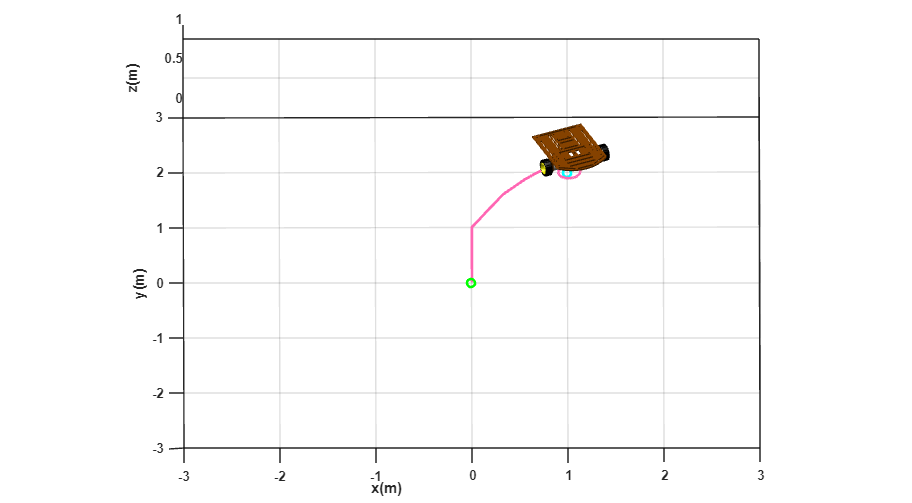

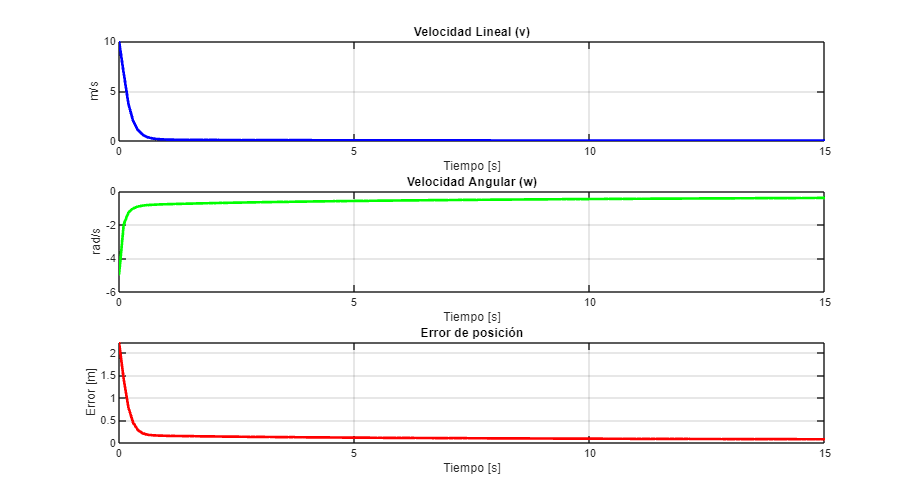

Inciso b)


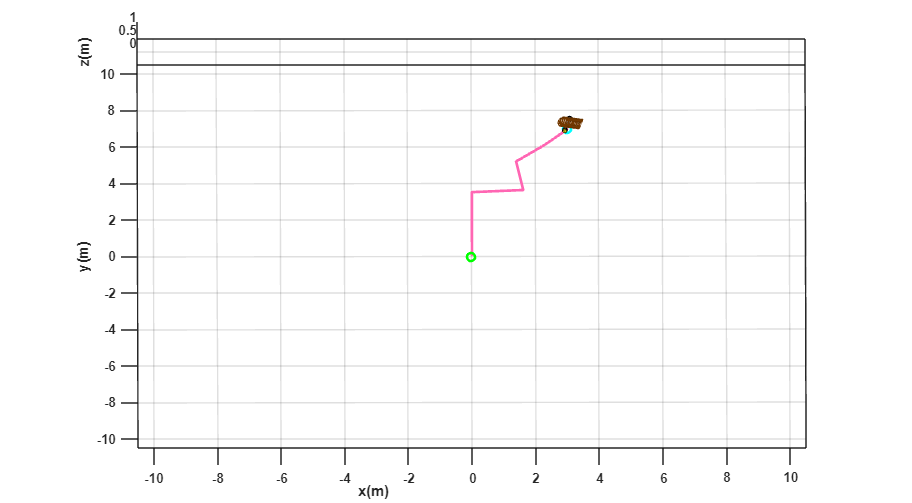

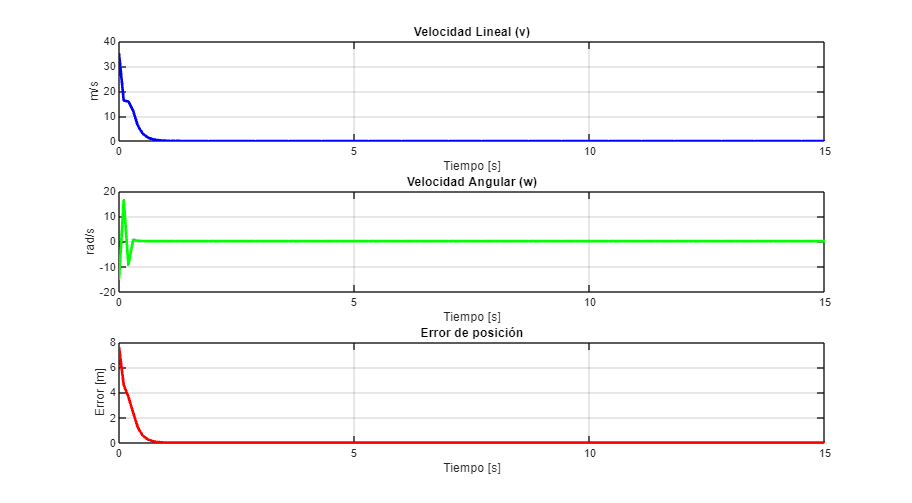

Inciso c)


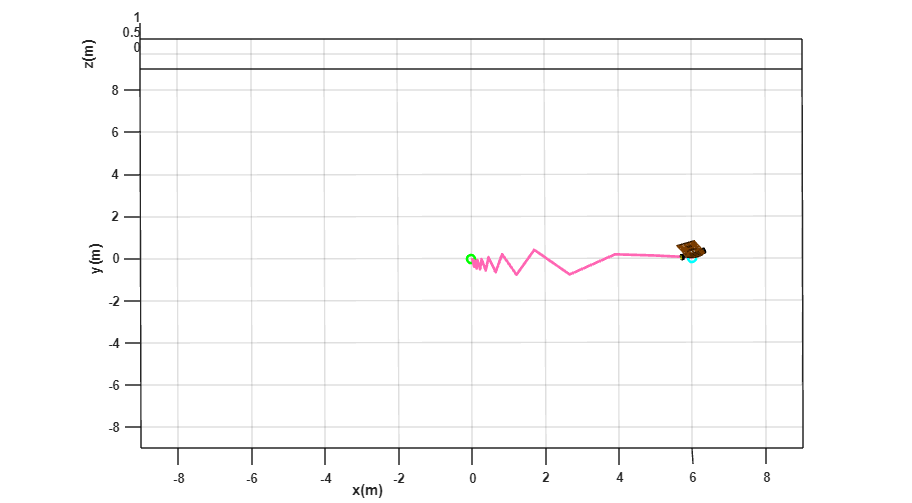

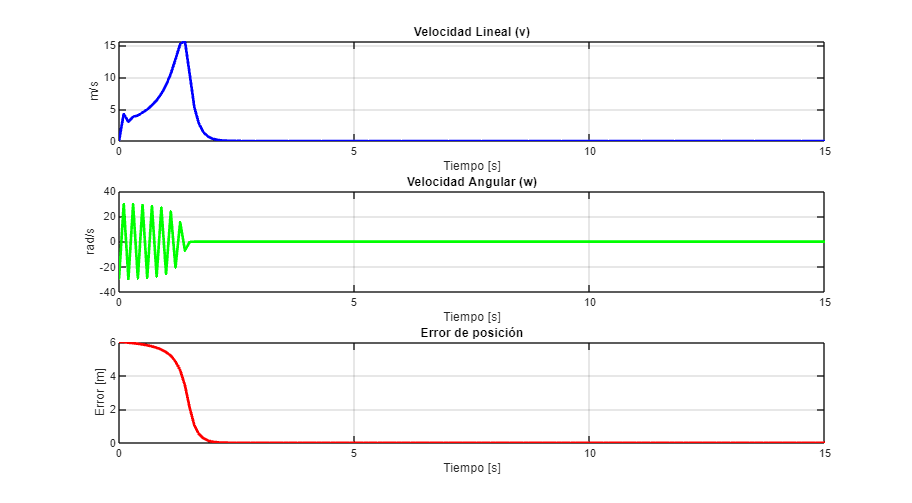

Inciso d)


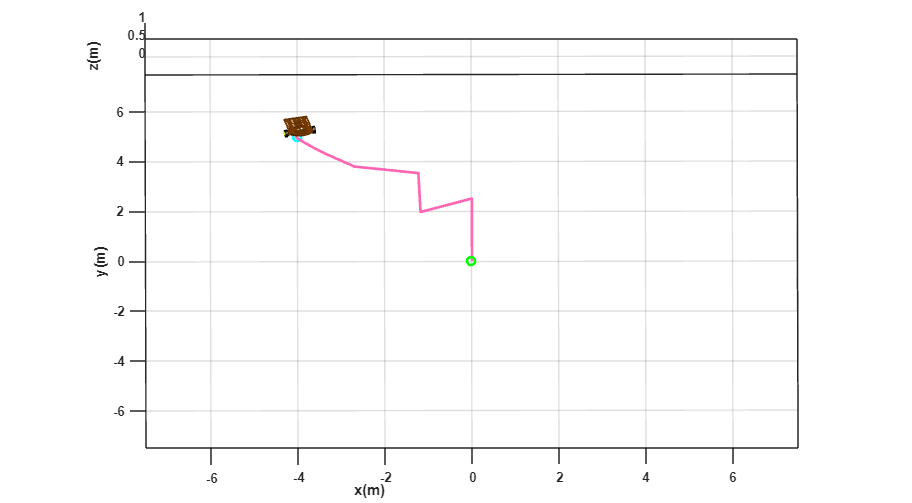

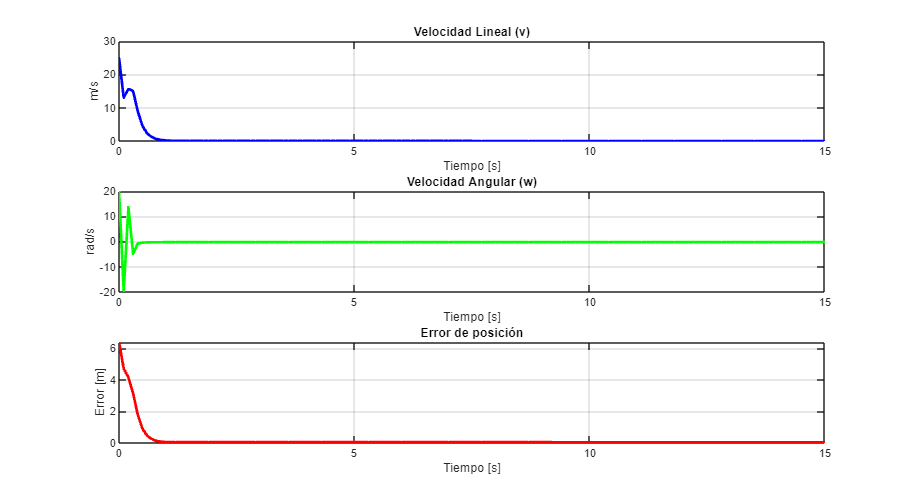

Inciso e)


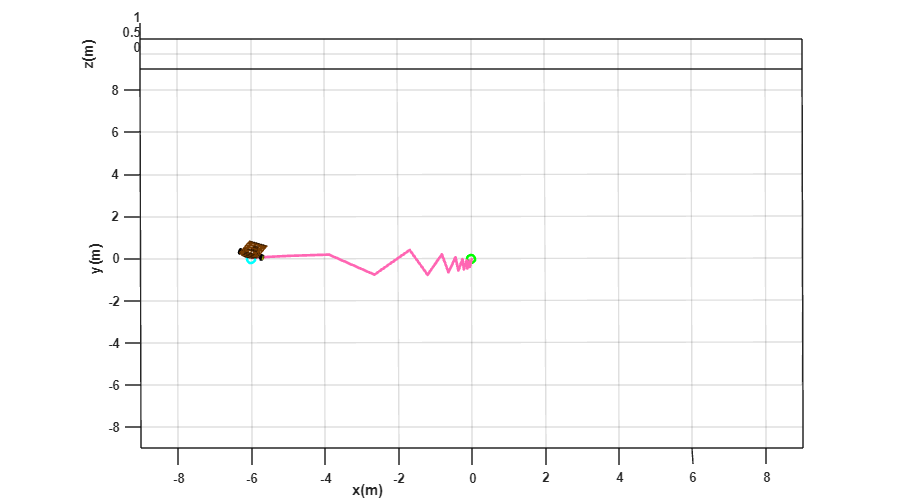

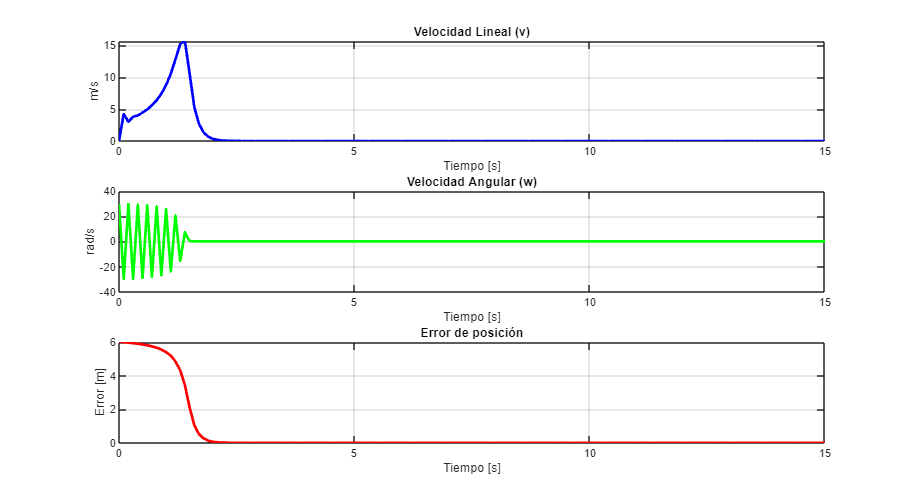

Inciso f)


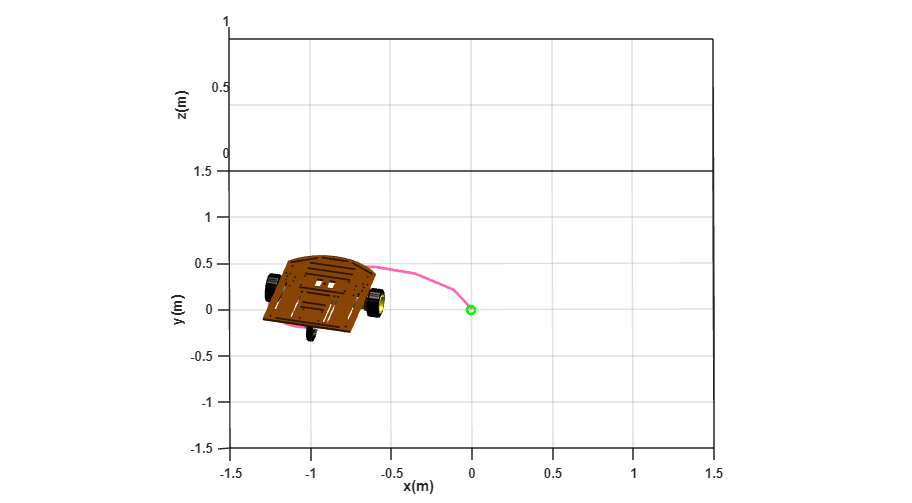

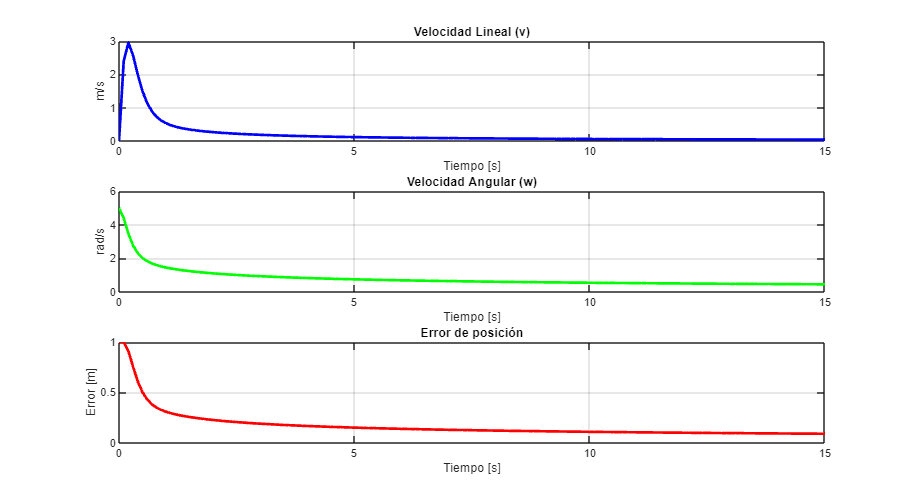

Inciso g)


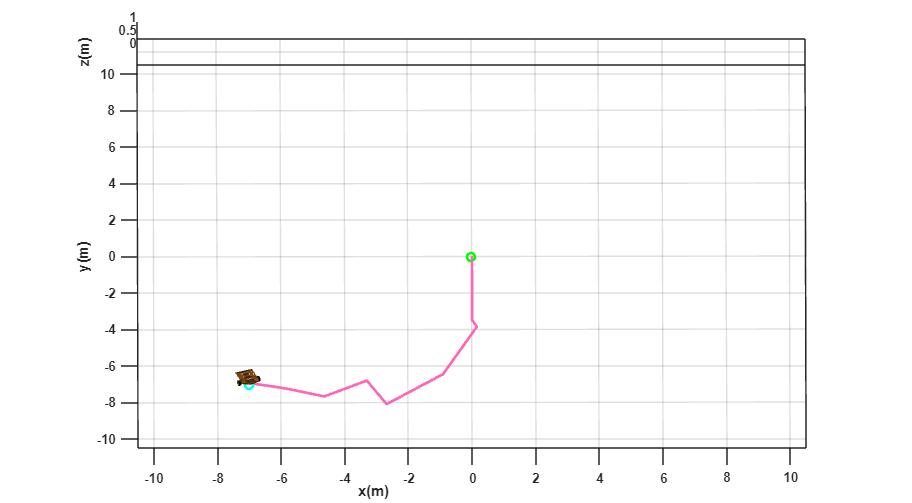

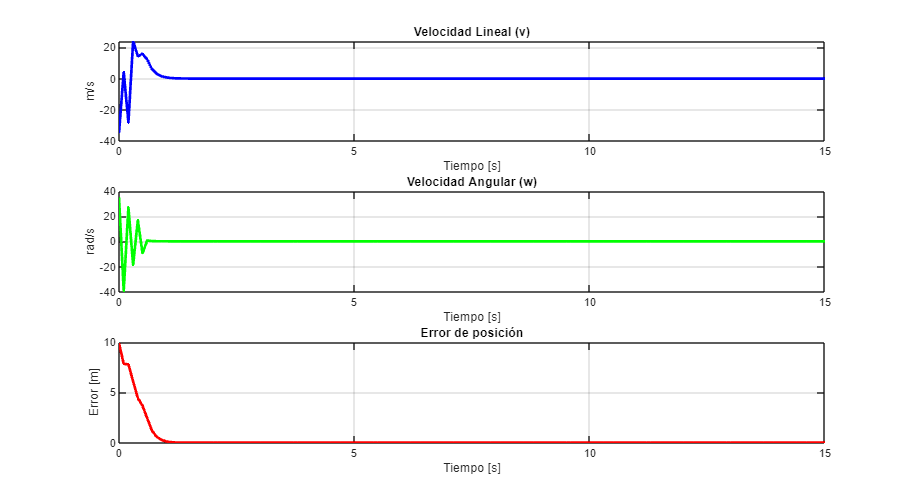

Inciso h)


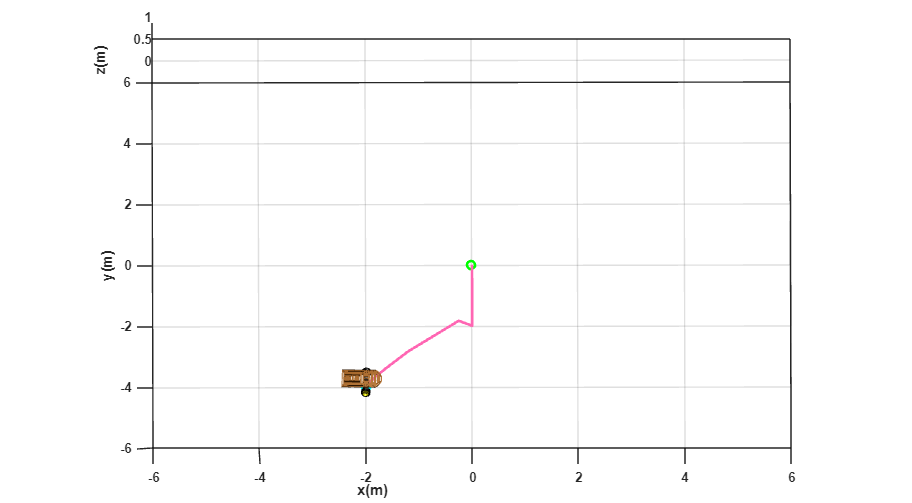

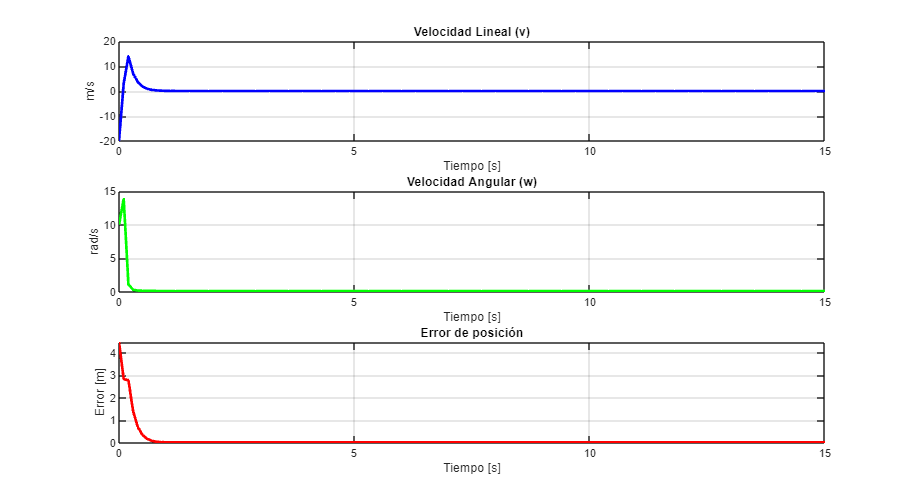

Inciso i)


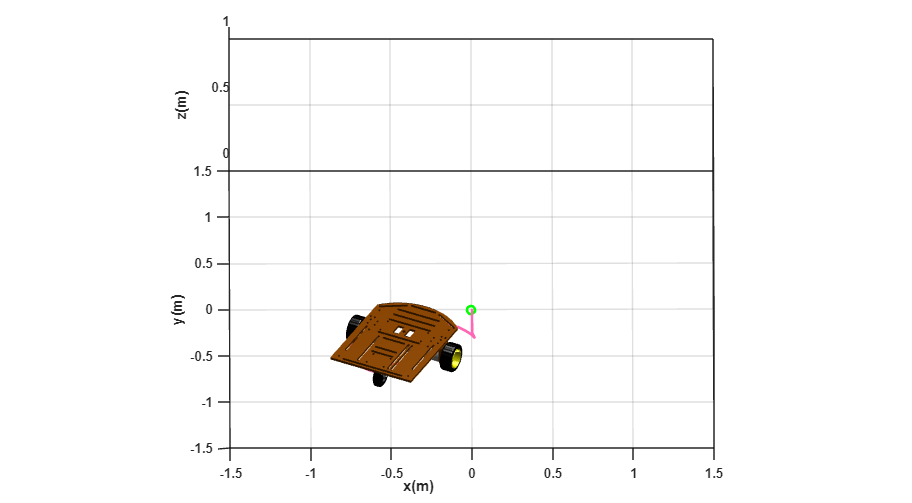

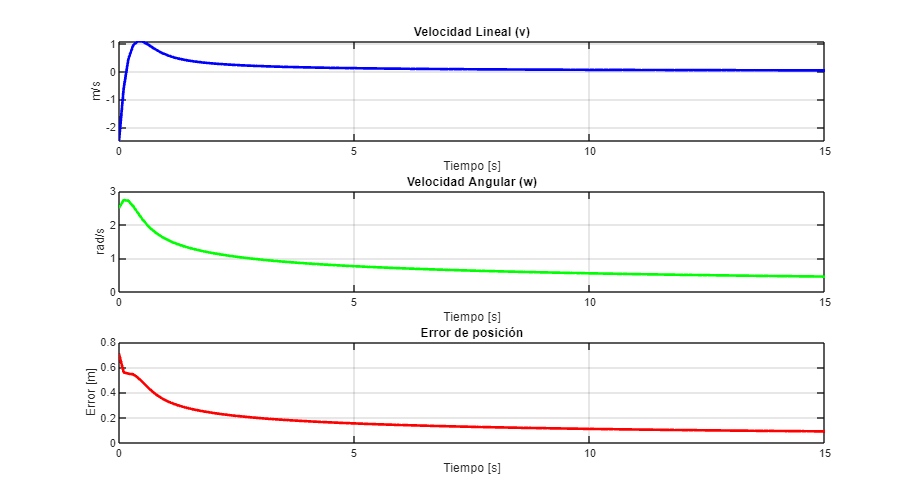

Inciso j)


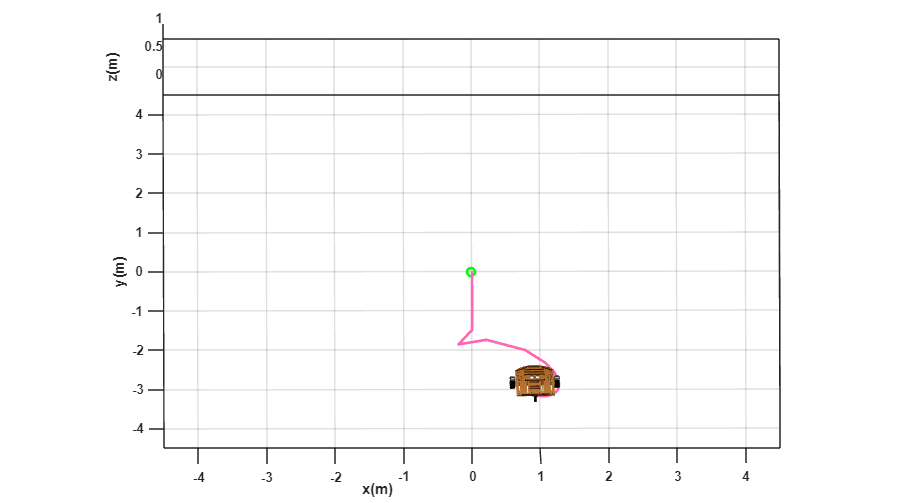

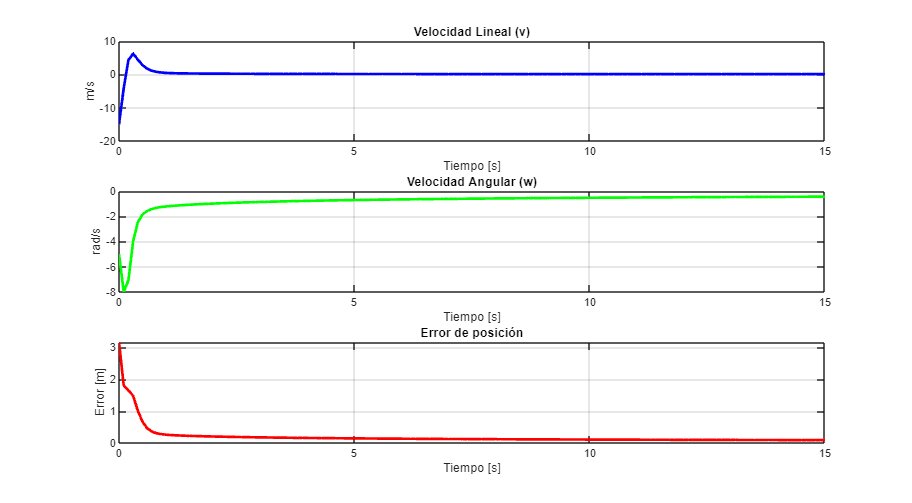

Inciso k)


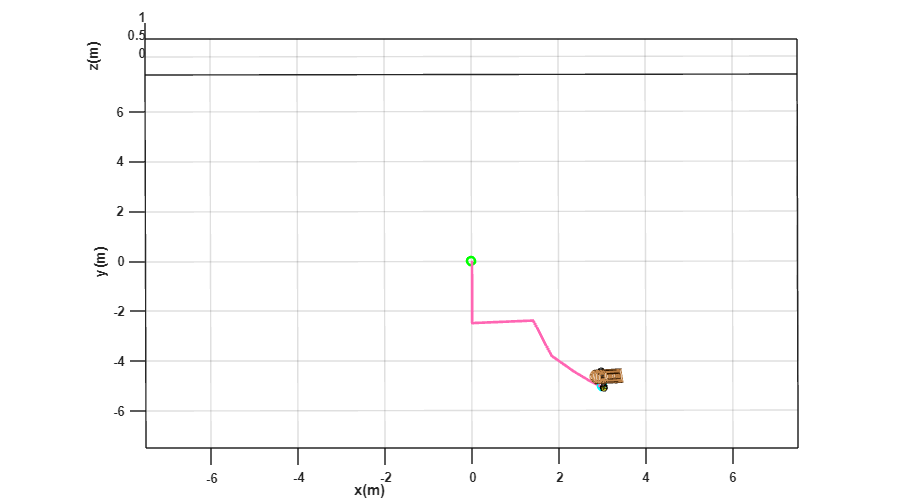

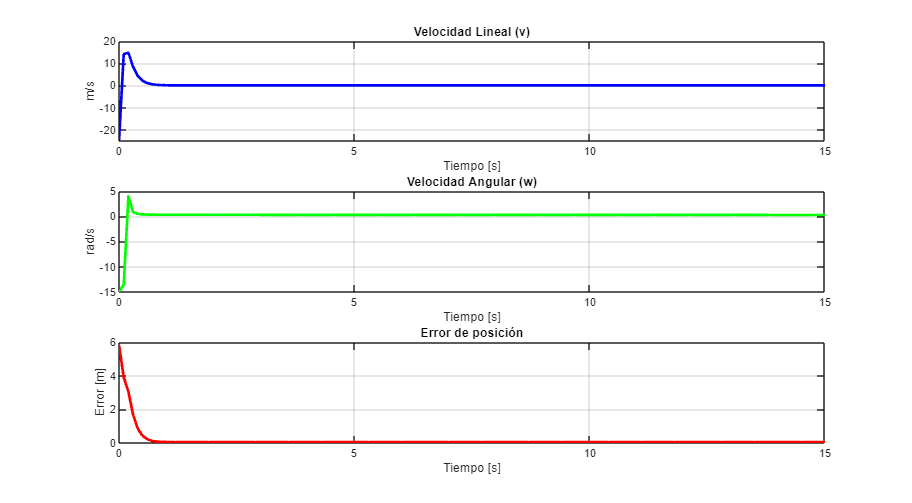

Inciso l)


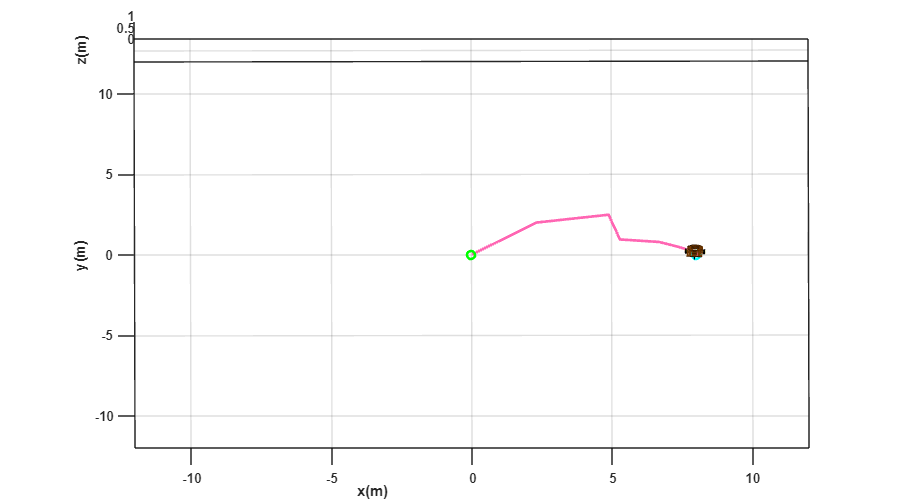

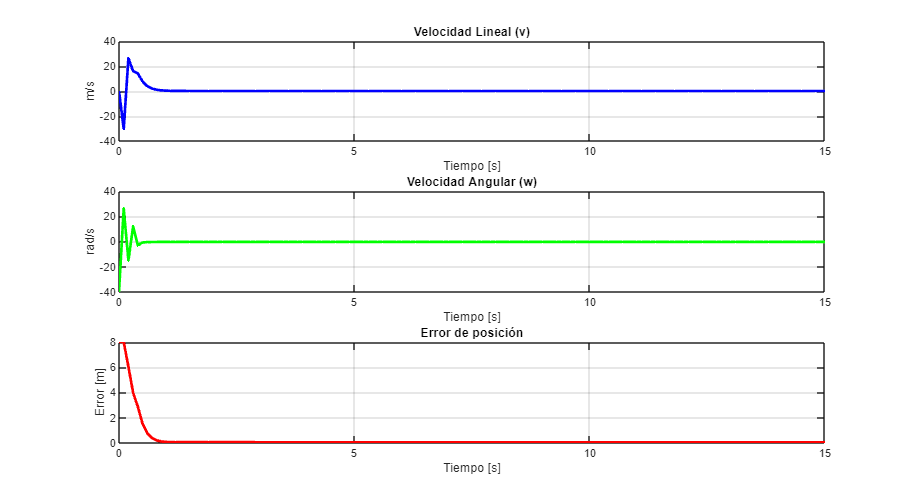

Inciso m)


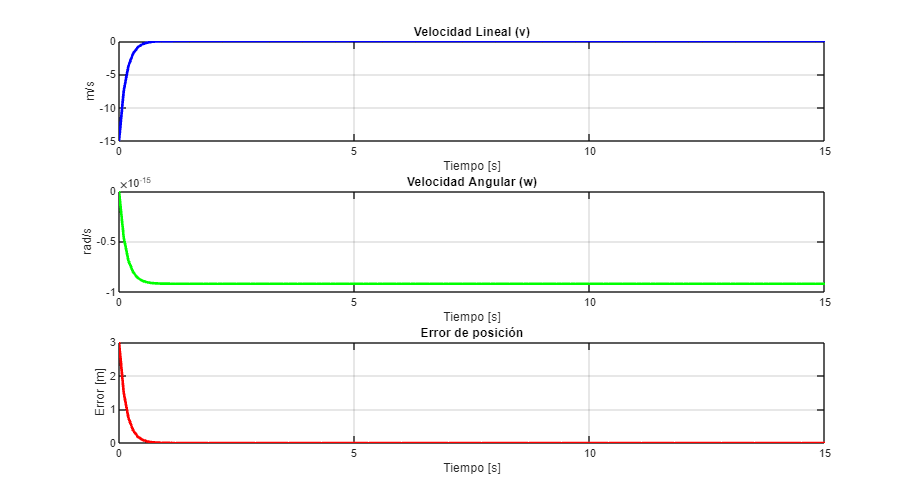

Inciso n)


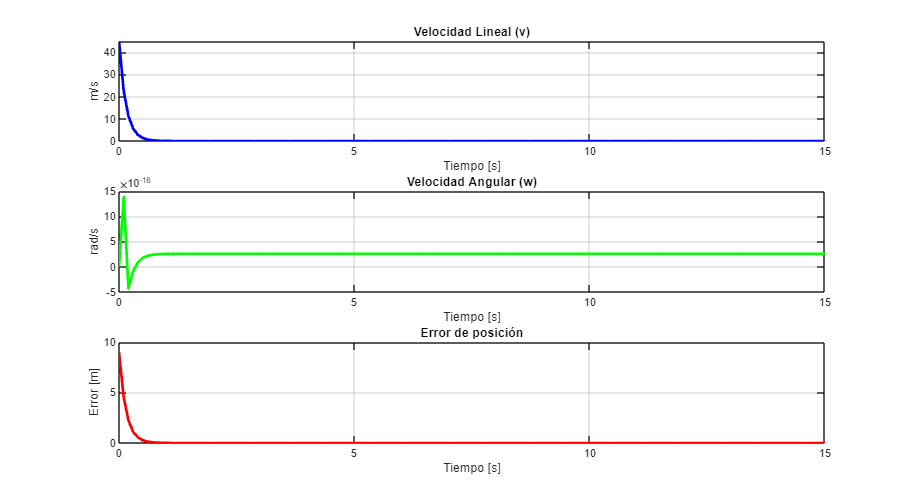

Inciso o)


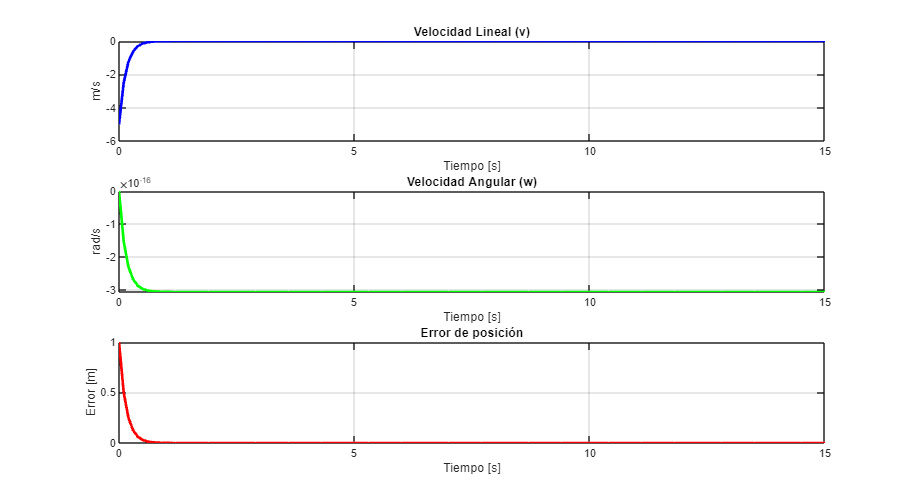

Inciso p)


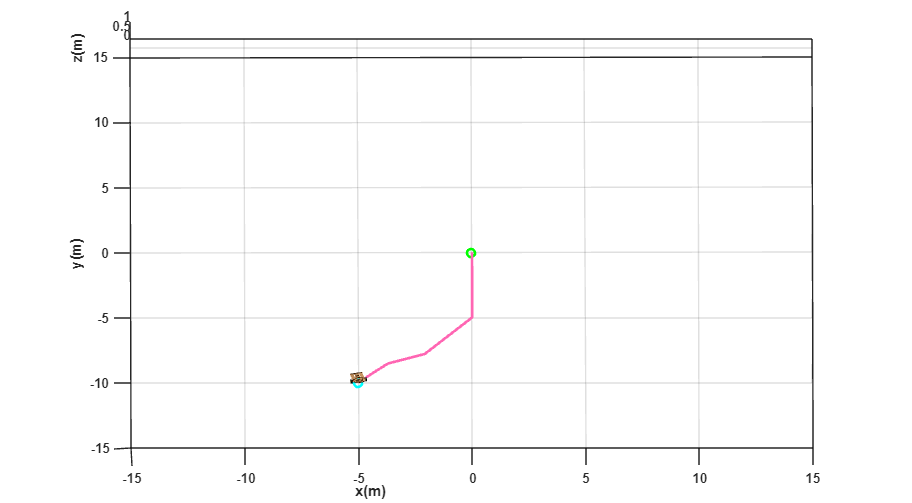

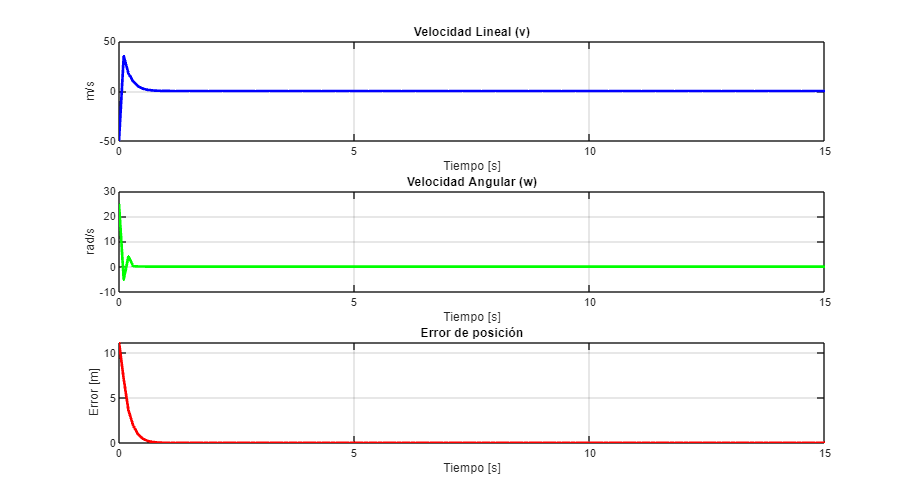

Inciso q)


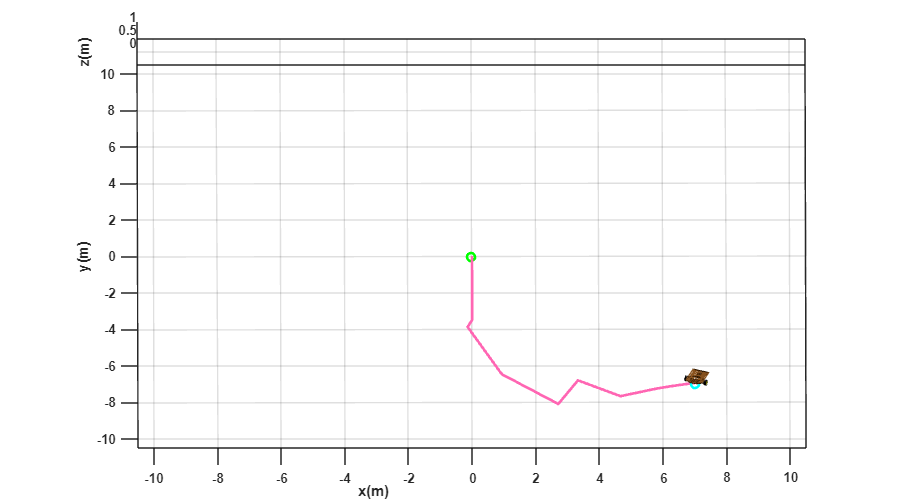

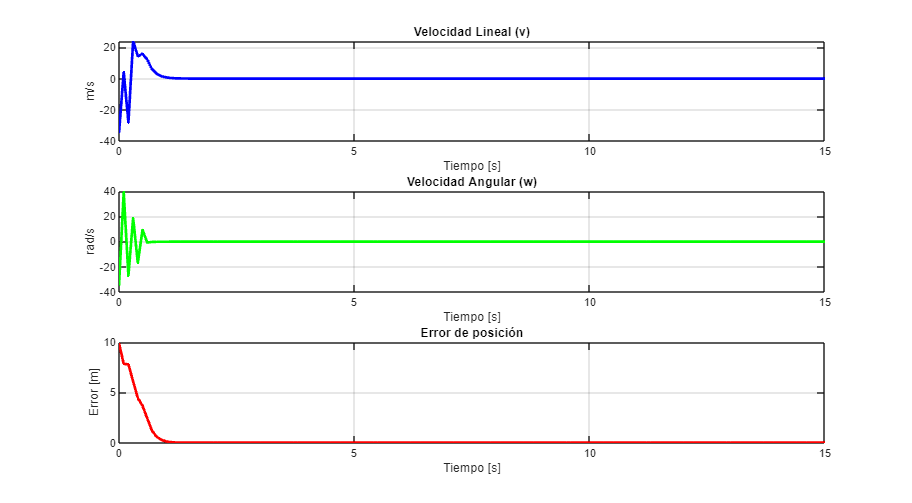

Inciso r)


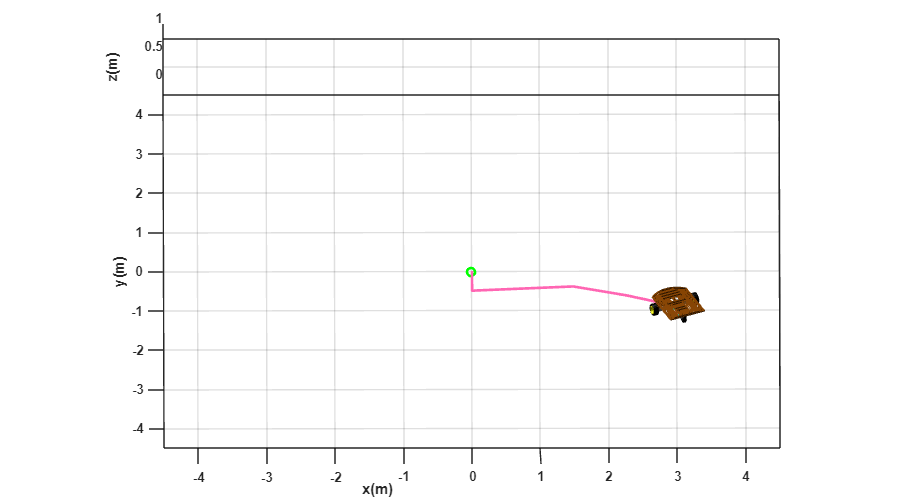

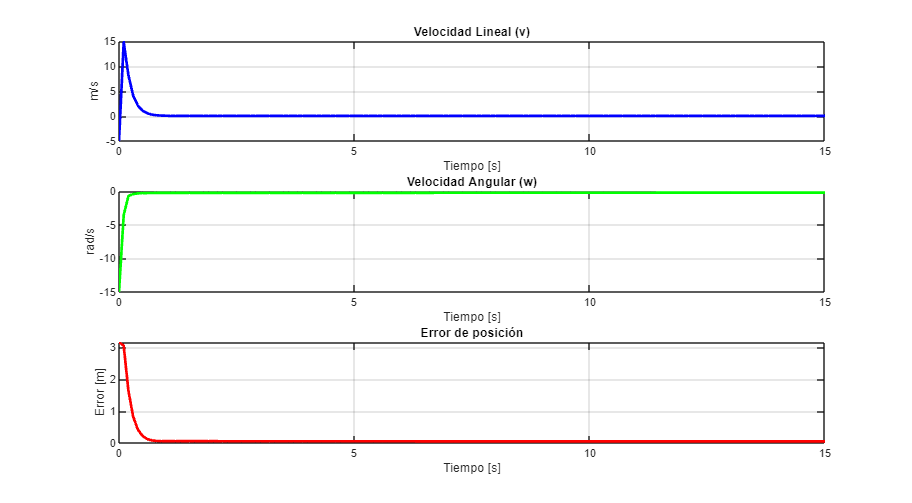

Inciso s)


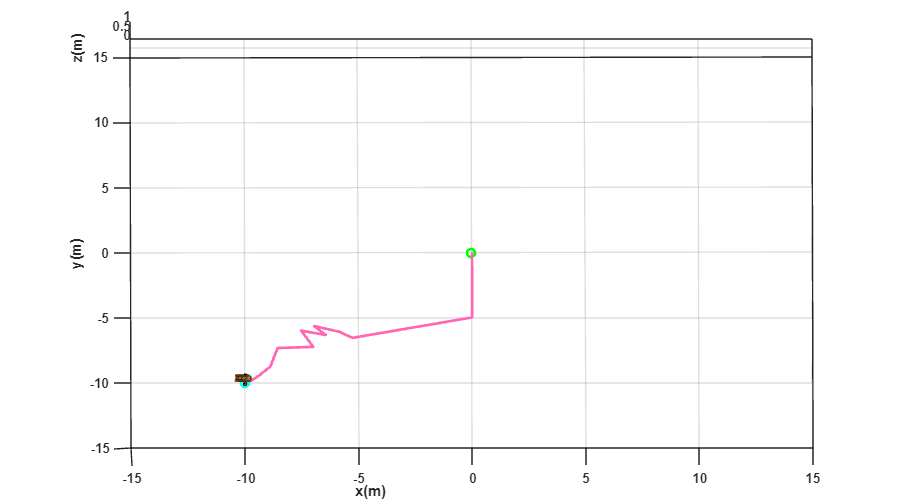

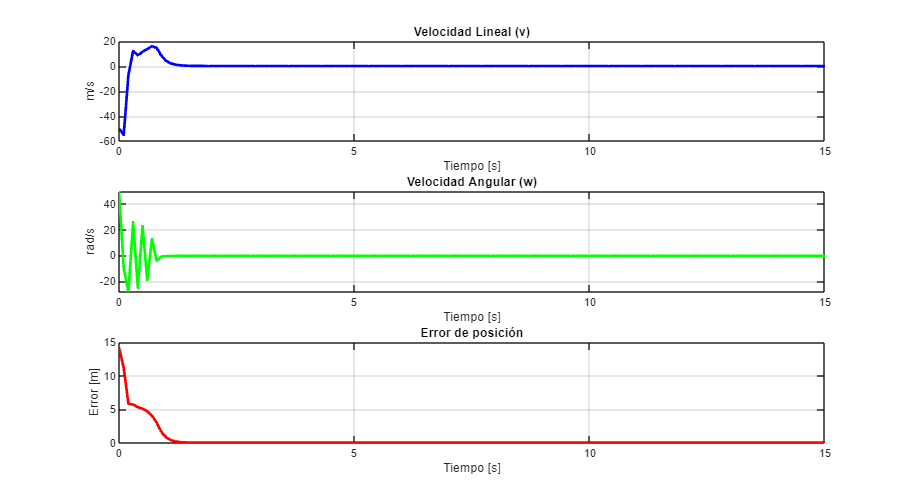

Inciso t)


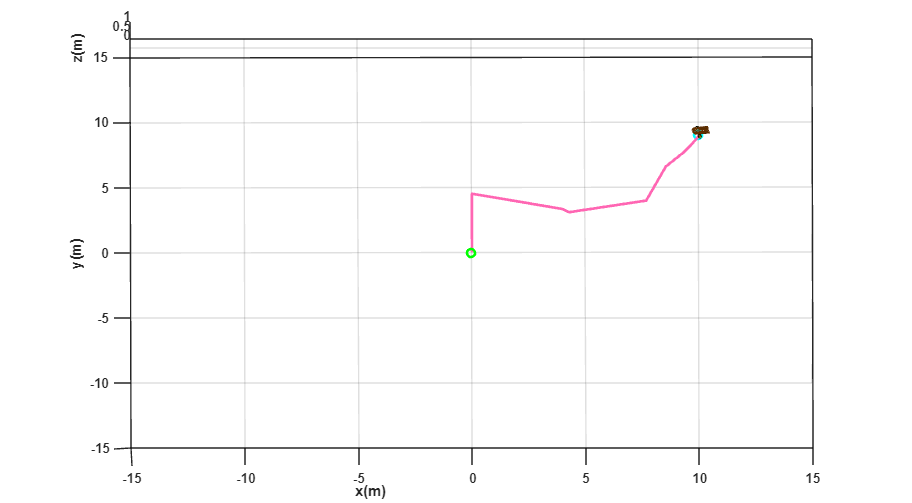

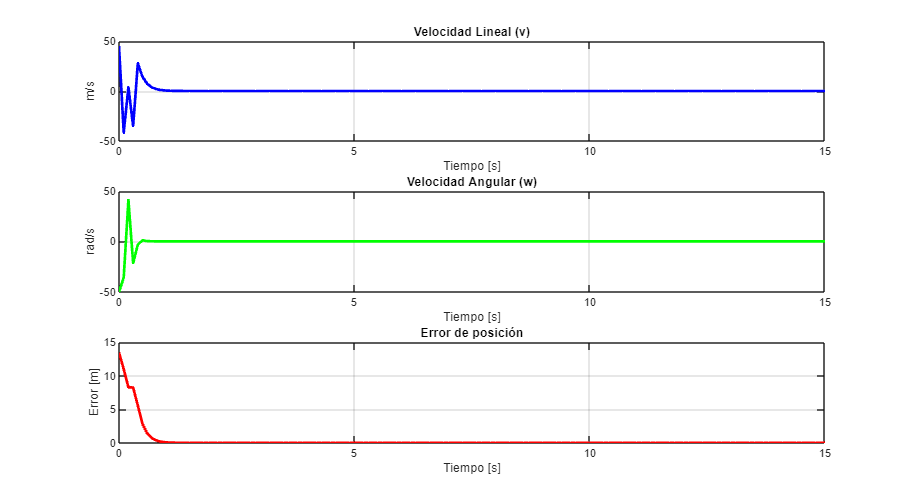

    graph = figure('Name',['Gráficas punto ' char(96+i)], 'position', sizeScreen);

    subplot(311)
    plot(t, v, 'b', 'LineWidth', 2); grid on;
    xlabel('Tiempo [s]'); ylabel('m/s');
    title('Velocidad Lineal (v)');

    subplot(312)
    plot(t, w, 'g', 'LineWidth', 2); grid on;
    xlabel('Tiempo [s]'); ylabel('rad/s');
    title('Velocidad Angular (w)');

    subplot(313)
    plot(t, Error, 'r', 'LineWidth', 2); grid on;
    xlabel('Tiempo [s]'); ylabel('Error [m]');
    title('Error de posición');
    
    pause(1); % Espera entre puntos
end

## Bucle de iteración 3: K = [15 0; 0 15];

sizeScreen = get(0,'ScreenSize');
scale = 4;

for i = 1:size(puntos_deseados,1)   

### Posición deseada

Se define el objetivo fijo al que debe llegar el robot (`hxd`, `hyd`).

    hxd = puntos_deseados(i,1);
    hyd = puntos_deseados(i,2);

### Condiciones iniciales

Se establecen las condiciones iniciales del robot: su posición en el plano (x, y) y su orientación (`phi`) medida en radianes. En este caso, el robot comienza en el origen apuntando hacia

    x1(1) = 0;
    y1(1) = 0;
    phi(1) = pi/2;

Inicialmente, la posición del punto de control del robot coincide con su posición actual (`hx`, `hy`).

    hx(1)=x1(1);
    hy(1)=y1(1);

    % Inicialización
    v = zeros(1,N); w = zeros(1,N); Error = zeros(1,N);

### Control, bucle de simulación

Se ejecuta un bucle a lo largo del tiempo de simulación. En cada iteración se calcula el error en las coordenadas X e Y entre el objetivo y la posición actual. Luego, se calcula la magnitud total del error. 

    for k = 1:N 
        hxe = hxd - hx(k); hye = hyd - hy(k);
        he = [hxe; hye];
        Error(k) = norm(he);

 Se construye la matriz Jacobiana que transforma errores en el marco global a comandos de movimiento en el marco del robot.

        J = [cos(phi(k)) -sin(phi(k)); sin(phi(k)) cos(phi(k))];

También se establece la matriz de ganancias proporcional para el controlador. Determina la agresividad con la que se corrige el error.

        K = [15 0; 0 15];

Se aplica una ley de control basada en la pseudoinversa del Jacobiano para obtener las velocidades lineal (`v`) y angular (`w`) que minimizan el error.

        qpRef = pinv(J) * K * he;
        v(k) = qpRef(1);
        w(k) = qpRef(2);

#### Aplicación del control al modelo cinemático

Se integran las velocidades para actualizar la orientación (`phi`) y posición (`x1`, `y1`) del robot utilizando el método de Euler. La posición del punto de control (`hx`, `hy`) se mantiene coincidente con el robot.

        phi(k+1) = phi(k) + w(k)*ts;
        xp1 = v(k)*cos(phi(k));
        yp1 = v(k)*sin(phi(k));
        x1(k+1) = x1(k) + xp1*ts;
        y1(k+1) = y1(k) + yp1*ts;
        hx(k+1) = x1(k+1);
        hy(k+1) = y1(k+1);
    end

### Simulacion virtual 3D 

Tras la simulación cinemática, se configura un entorno 3D para visualizar el comportamiento del robot. Se crea una figura de tamaño completo con fondo blanco, se ajustan los ejes con proporciones iguales y se establecen etiquetas y cuadrículas para facilitar la lectura del entorno. Se coloca una luz en la escena y se orienta la vista para una mejor perspectiva. Los límites de visualización se establecen para acomodar el espacio que recorrerá el robot.

#### a) Configuracion de escena

    scene = figure('Name',['Animación punto ' char(96+i) ' → (' num2str(hxd) ',' num2str(hyd) ')']);
    set(scene, 'Color','white', 'position', sizeScreen);
    set(gca,'FontWeight','bold') ;
    sizeScreen=get(0,'ScreenSize');
    camlight('headlight');
    axis equal;
    grid on;
    box on;
    xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
    view([-0.1 35]);

    % Obtener coordenadas del punto deseado
    px = puntos_deseados(i,1);
    py = puntos_deseados(i,2);
    
    % Obtener el mayor valor absoluto entre x y y
    var = max([abs(px), abs(py), 1]); % Asegura al menos 1 metro de visibilidad
    lim = 1.5*var;
    
    % Establecer límites simétricos en x e y
    axis([-lim lim -lim lim 0 1]);

#### **b) Graficar robots en la posicion inicial**

    MobileRobot_5;
    H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;

#### **c) Graficar trayectorias**

    H2 = plot3(hx(1), hy(1), 0, 'Color', [1 0.4 0.7], 'LineWidth', 2);
    H3 = plot3(hxd, hyd, 0, 'co', 'LineWidth', 2); % Punto deseado
    H4 = plot3(hx(1), hy(1), 0, 'go', 'LineWidth', 2); % Punto inicial

#### **d) Bucle de simulacion de movimiento del robot**

    disp(['Inciso ' char(96+i) ')']);
    step = 1;
    for k = 1:step:N
        delete(H1);
        delete(H2);
        H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
        H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'Color', [1 0.4 0.7], 'LineWidth', 2);
        pause(ts);
    end

### Gráficas

Finalmente, se generan tres gráficas: velocidad lineal (`v`), velocidad angular (`w`), y el error de posición acumulado en el tiempo. Estas permiten analizar el desempeño del controlador.

Inciso a)


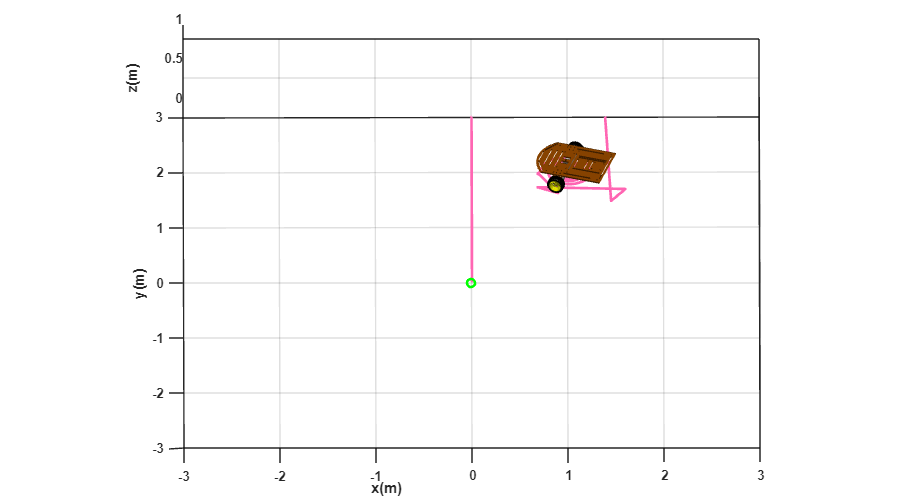

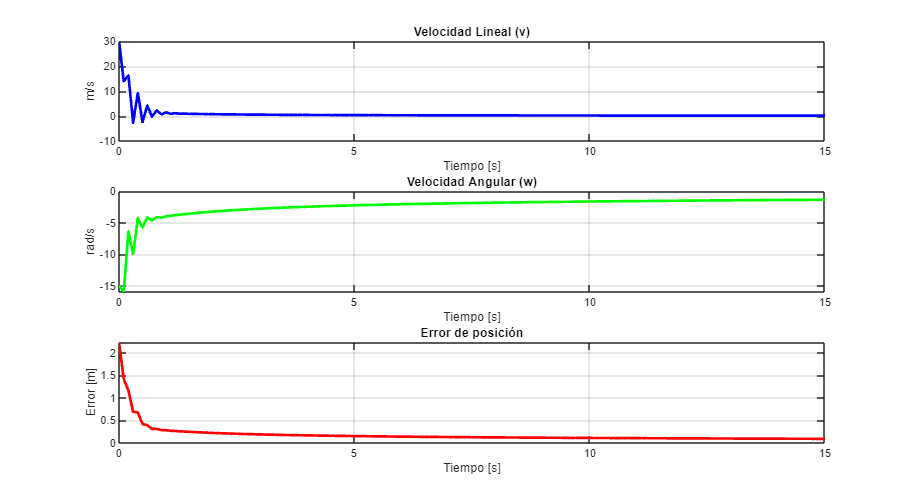

Inciso b)


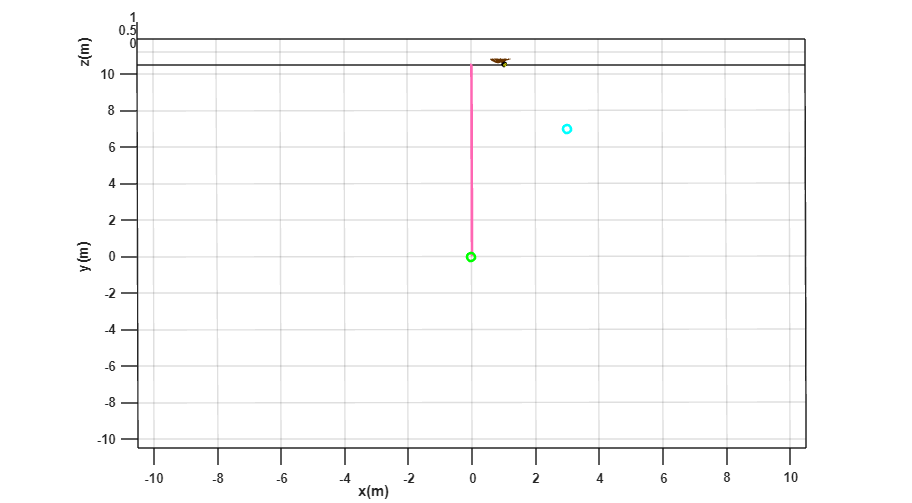

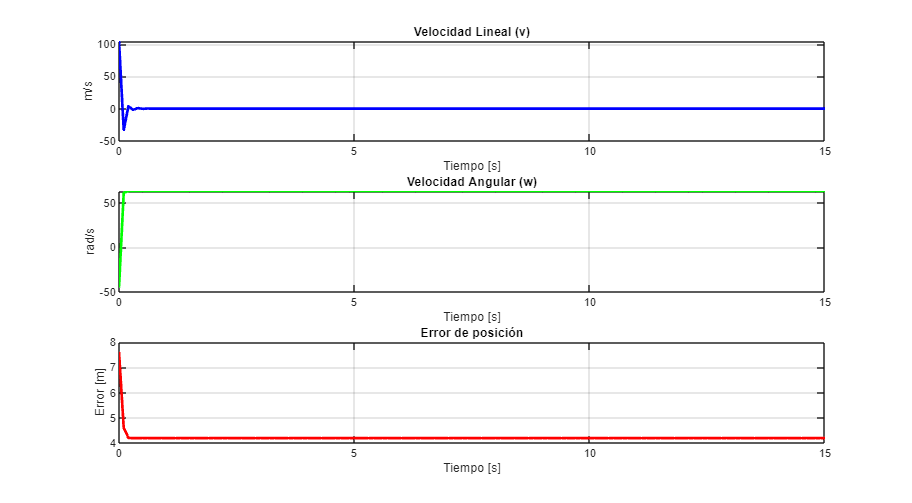

Inciso c)


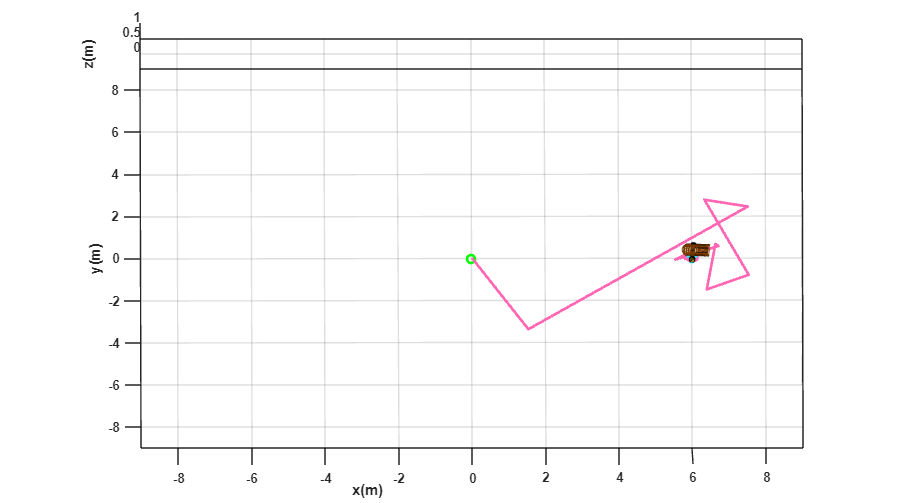

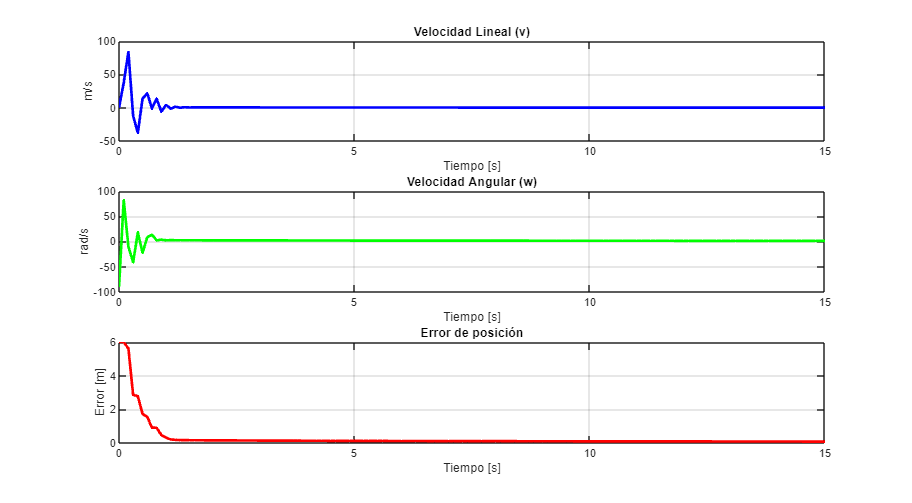

Inciso d)


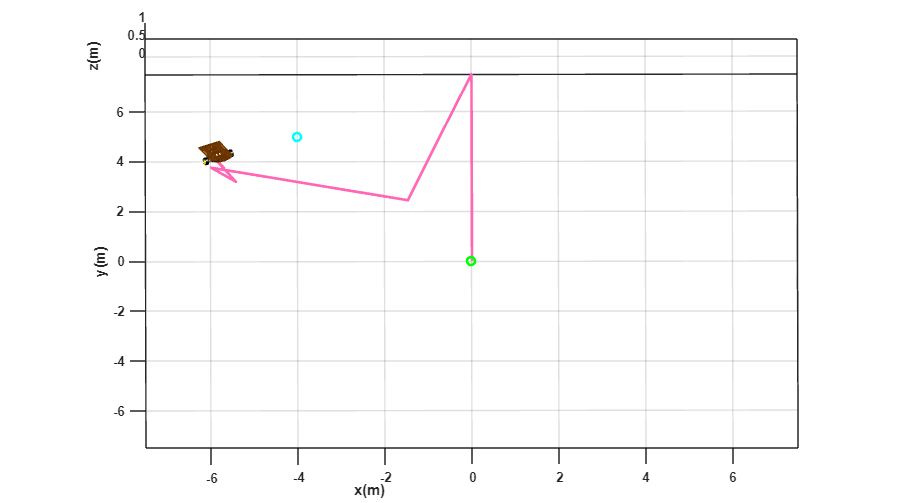

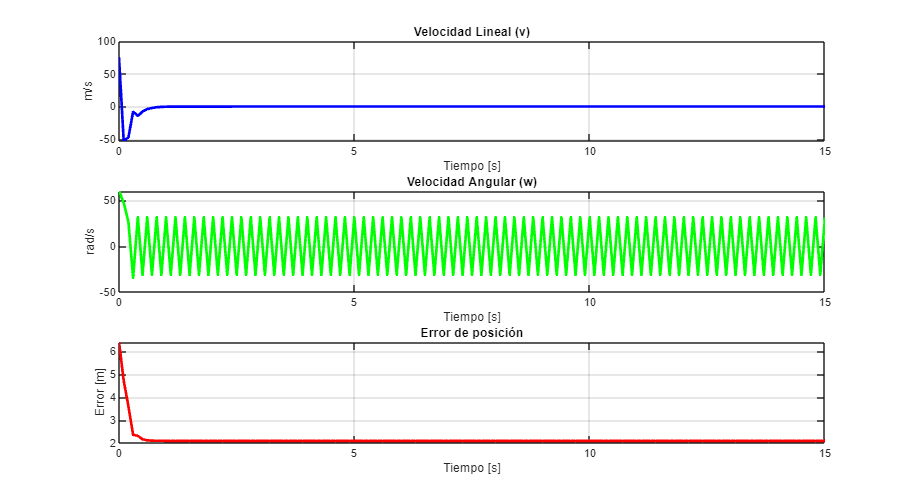

Inciso e)


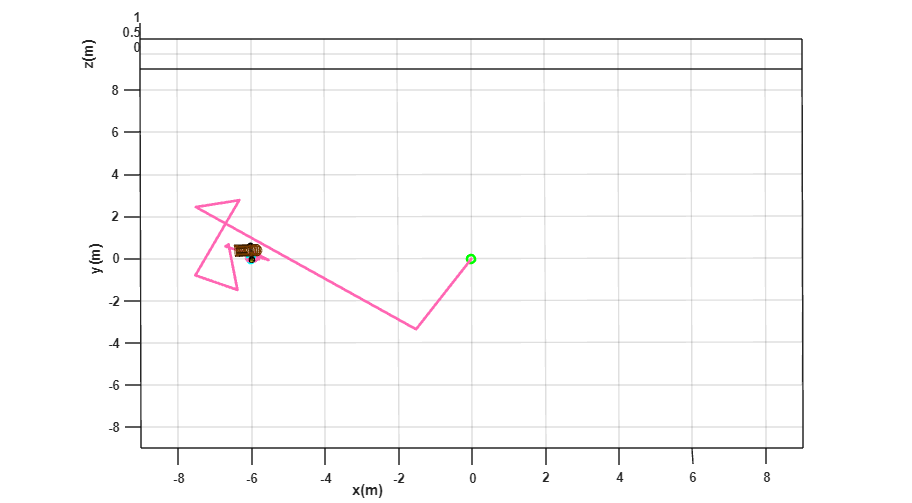

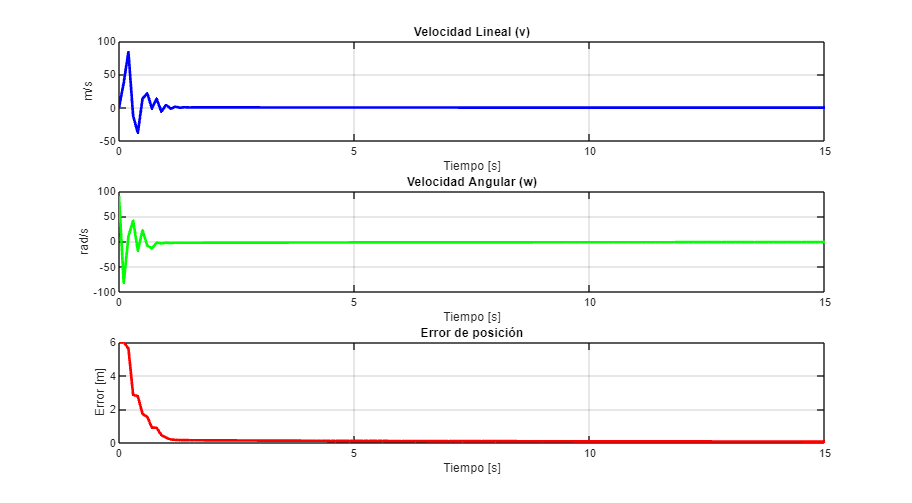

Inciso f)


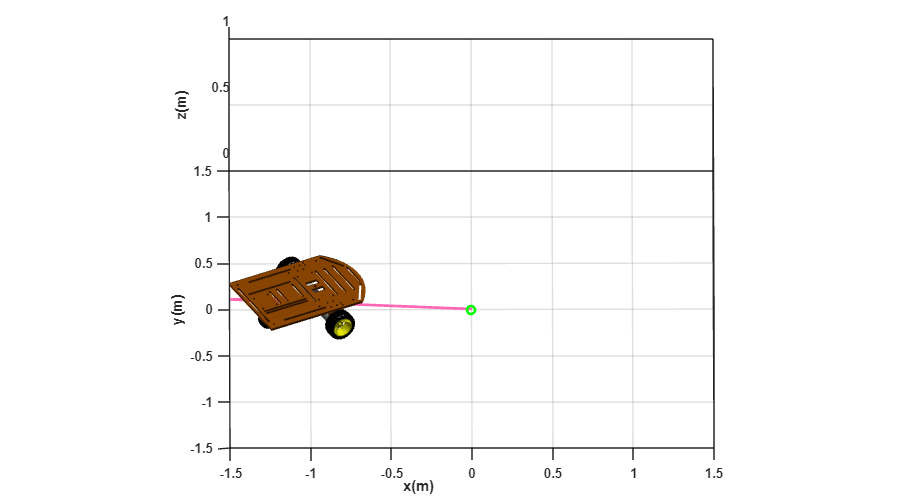

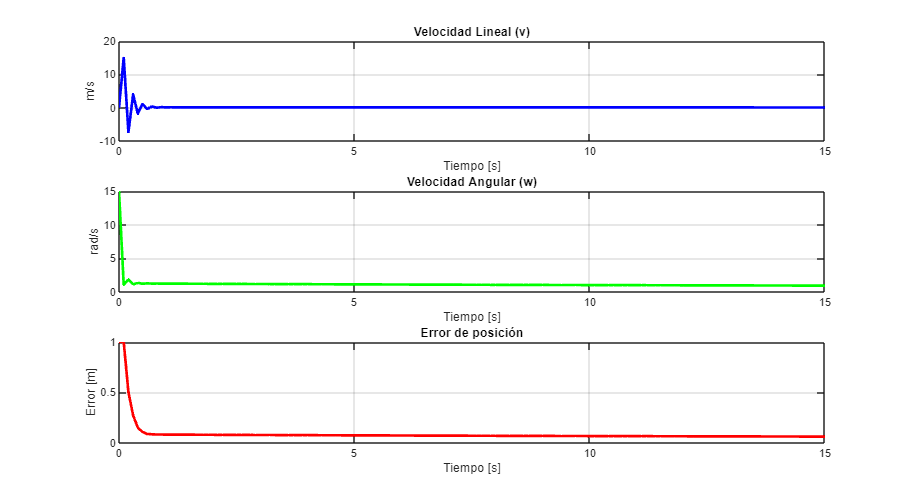

Inciso g)


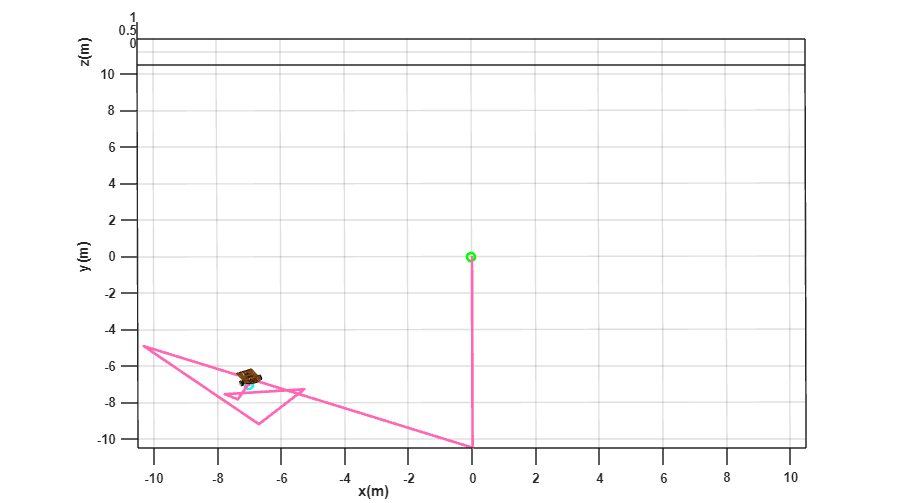

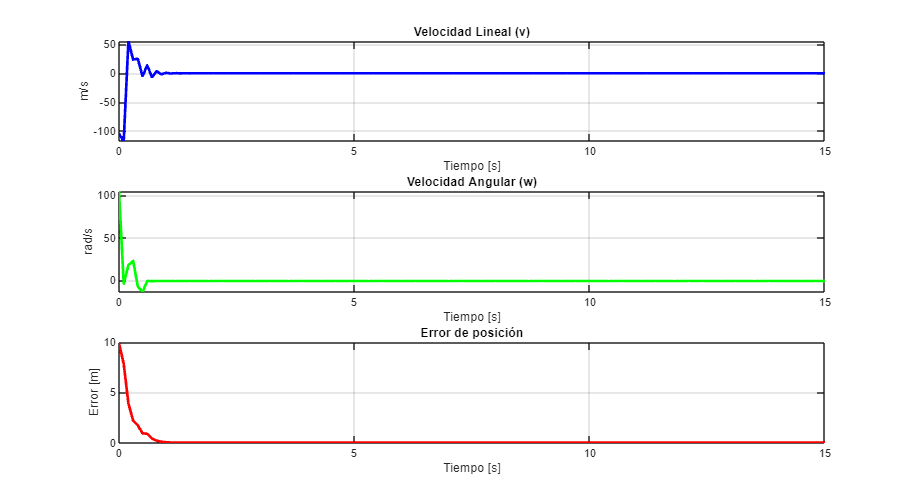

Inciso h)


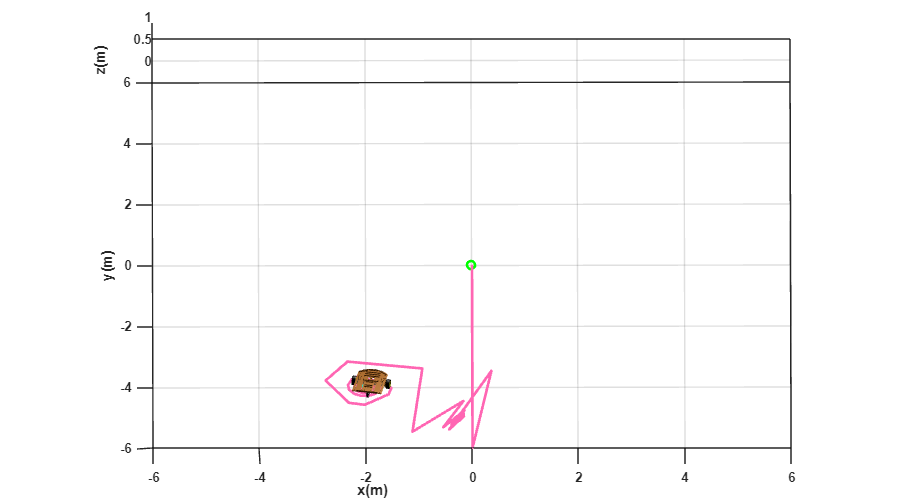

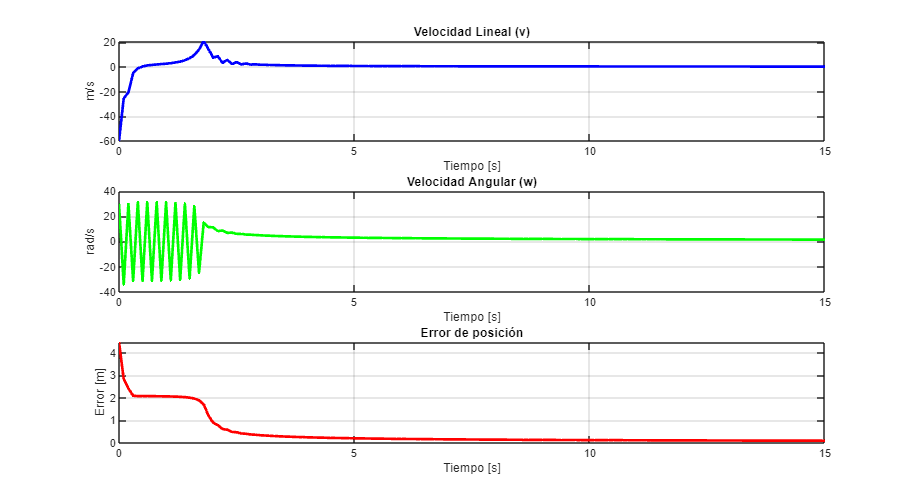

Inciso i)


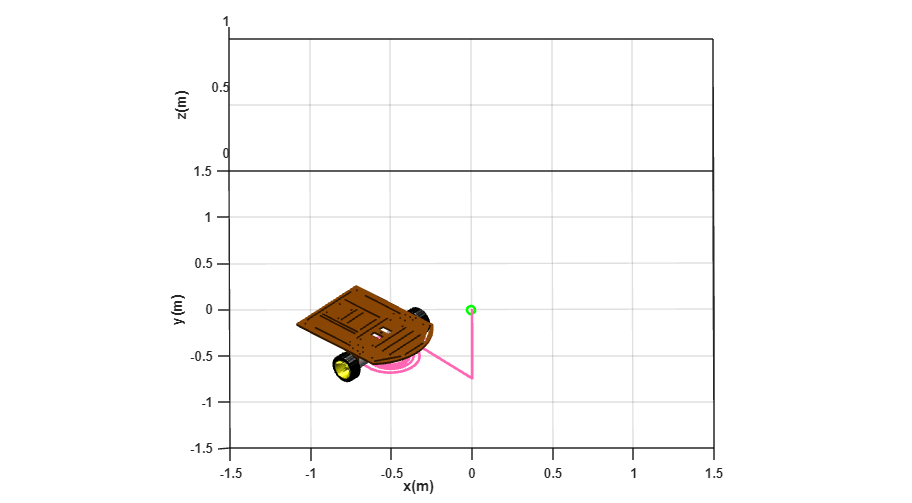

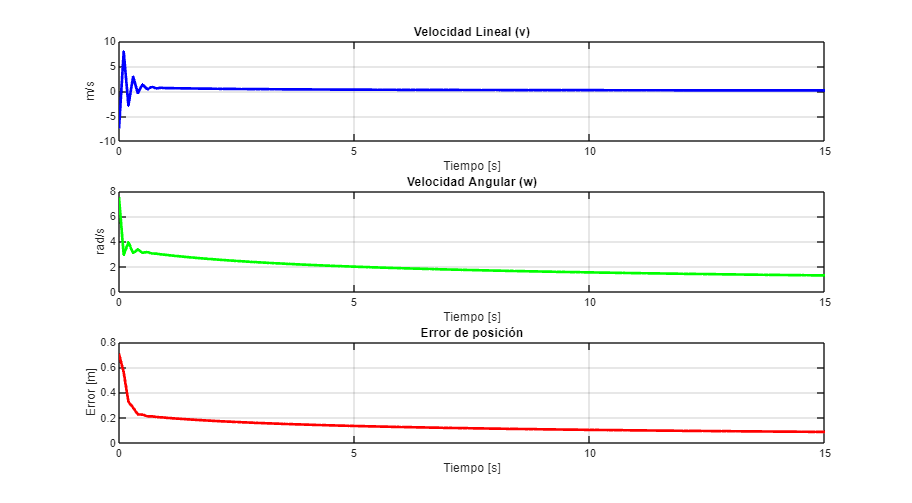

Inciso j)


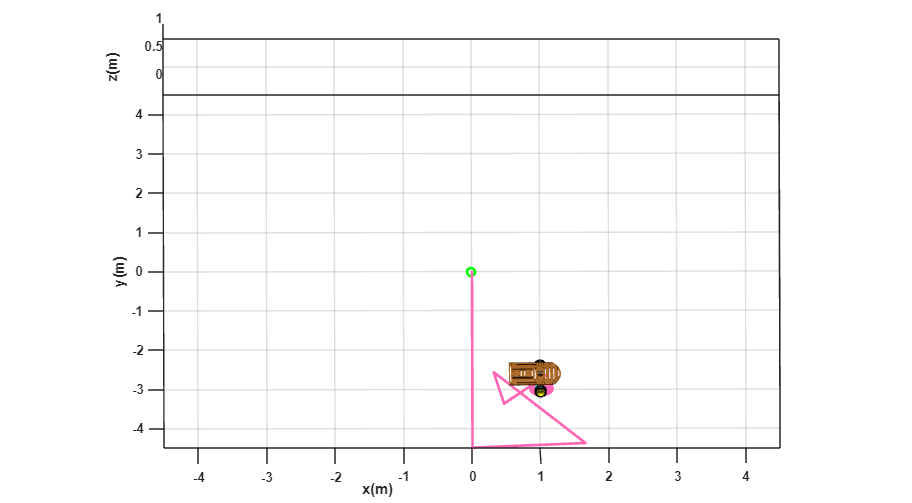

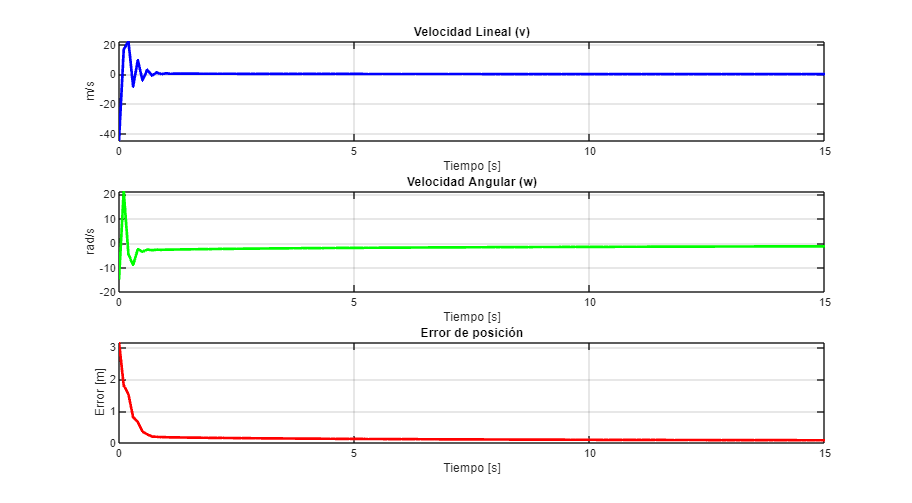

Inciso k)


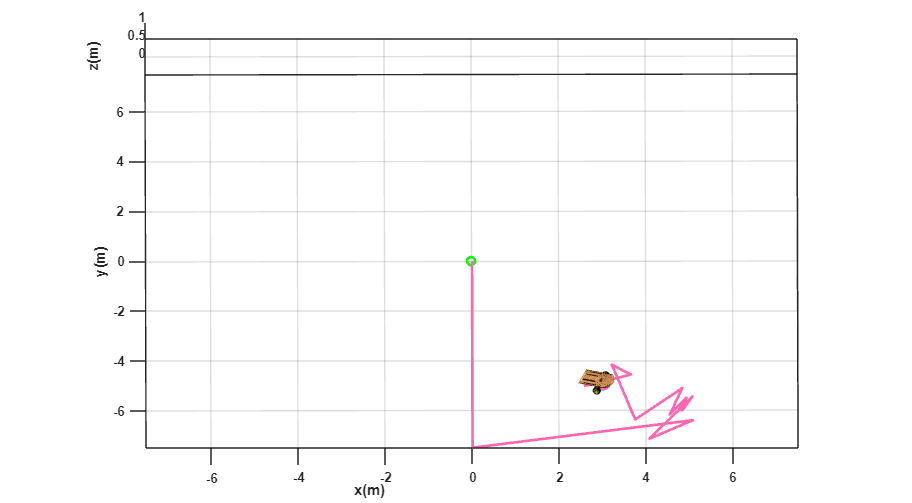

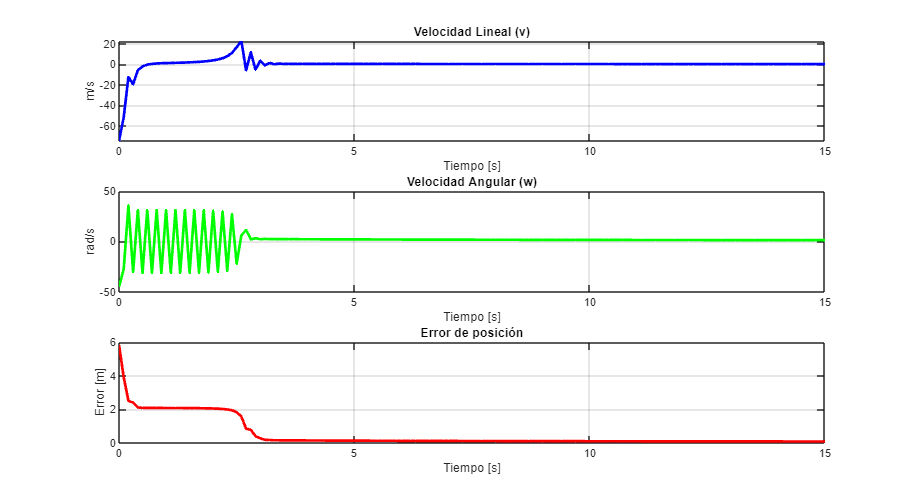

Inciso l)


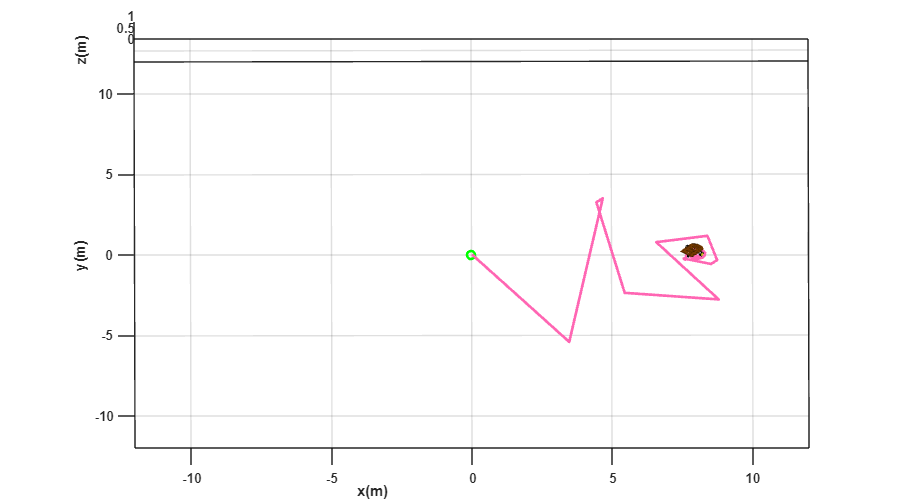

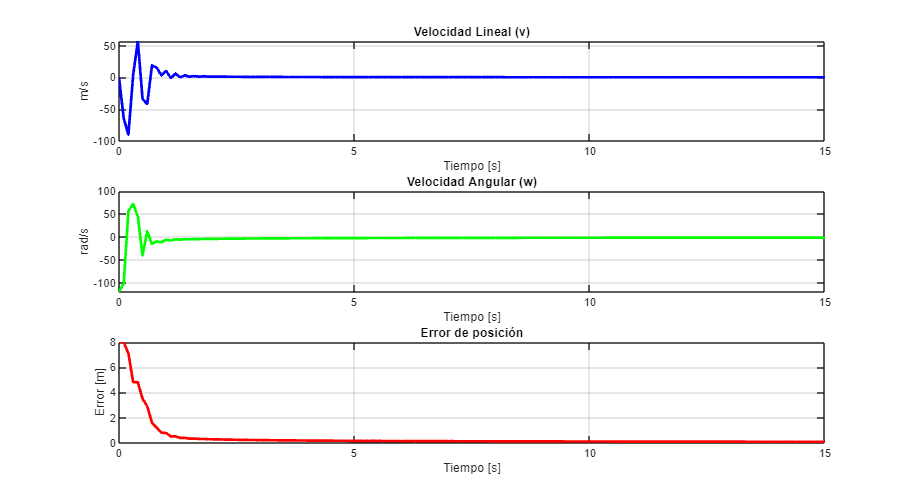

Inciso m)


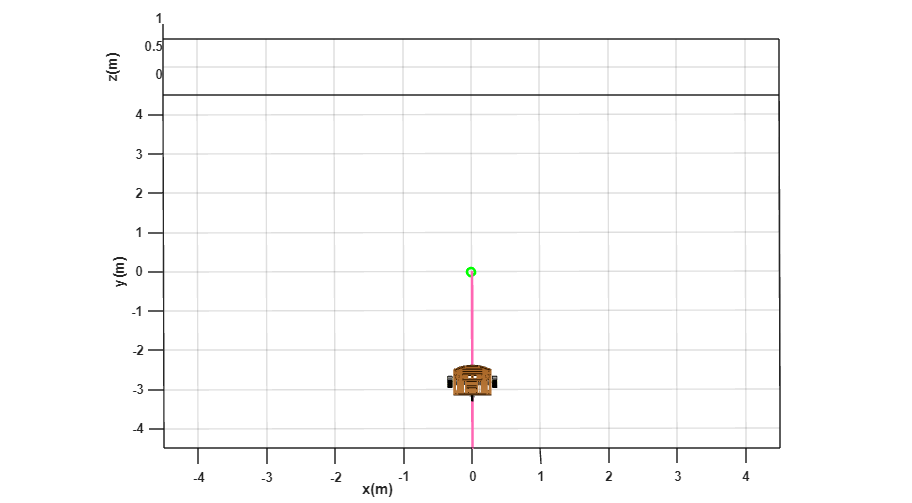

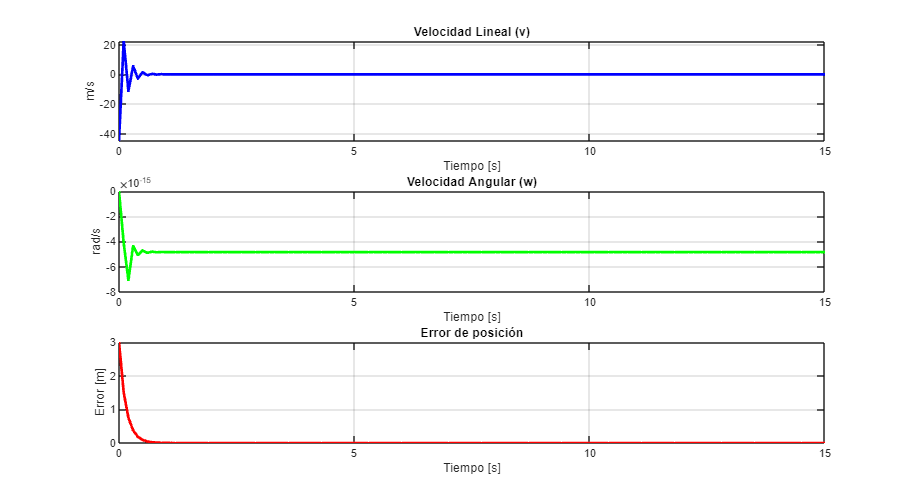

Inciso n)


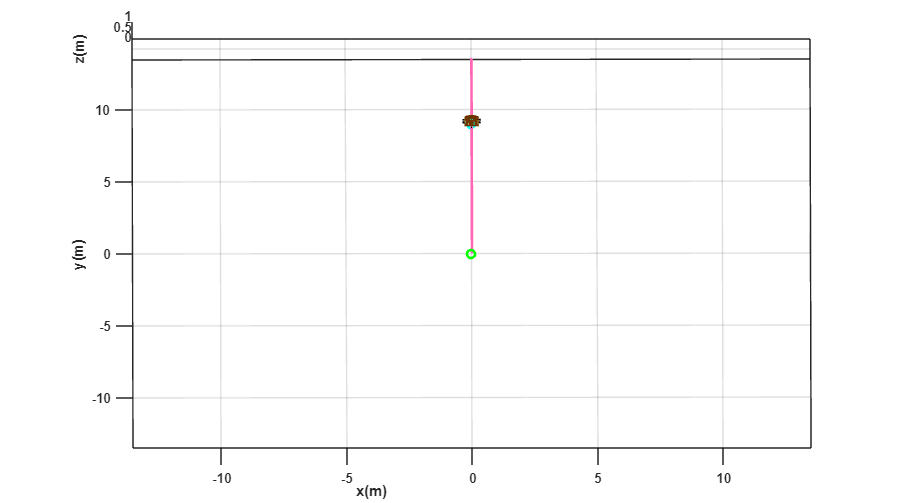

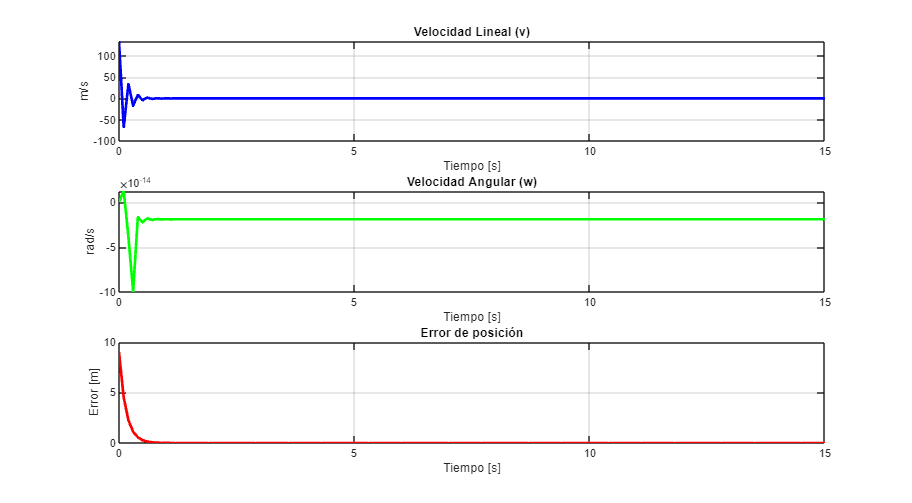

Inciso o)


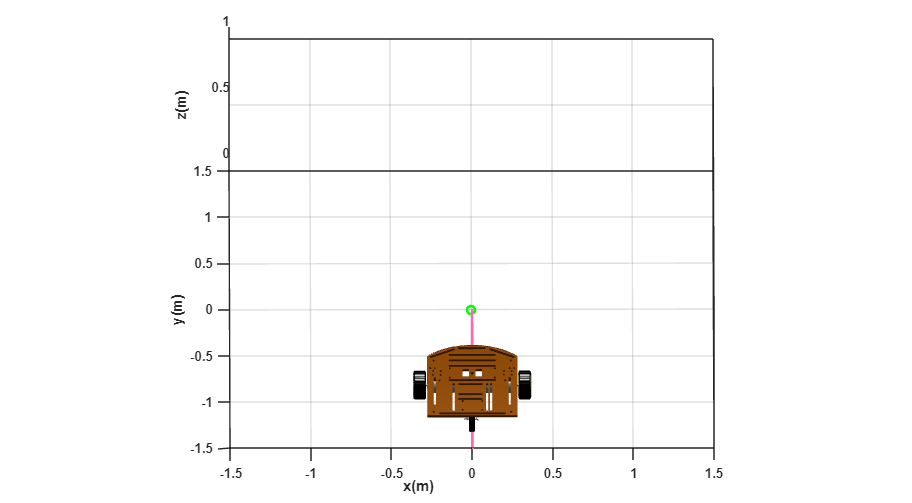

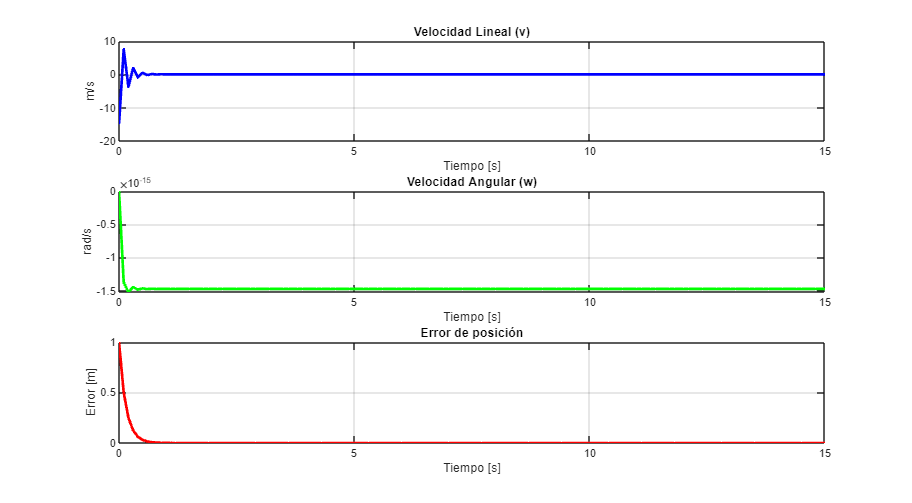

Inciso p)


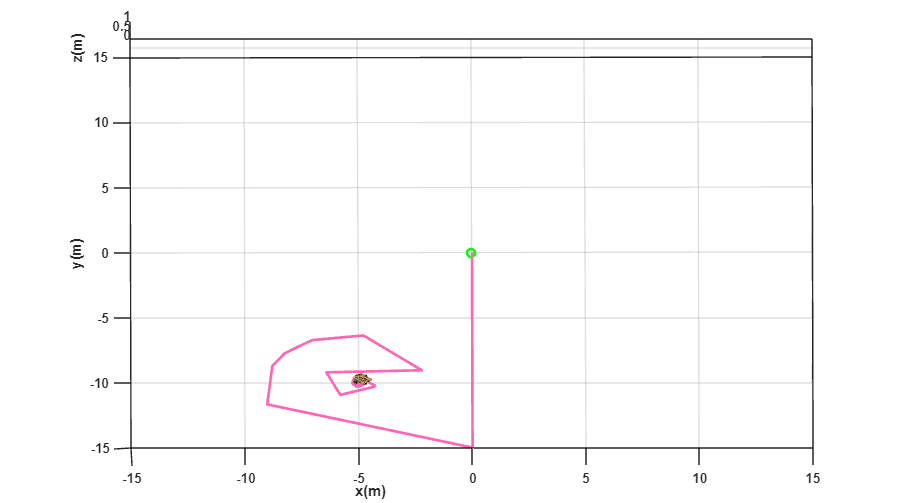

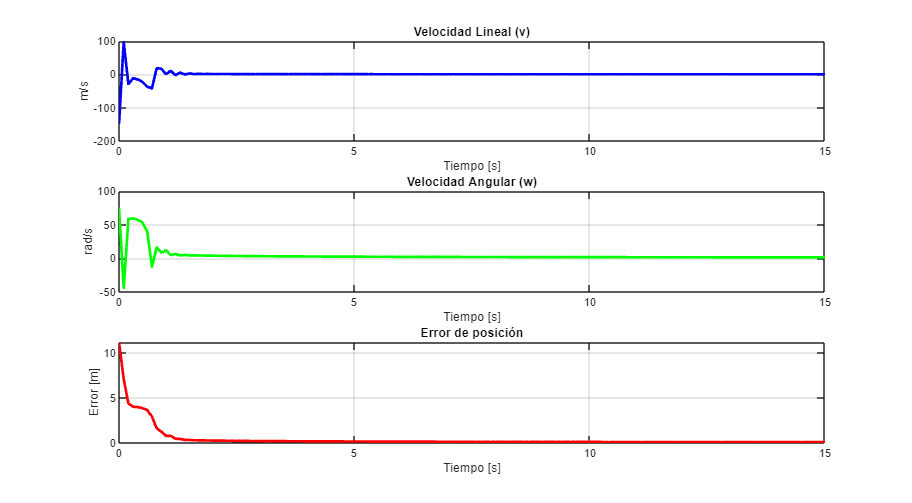

Inciso q)


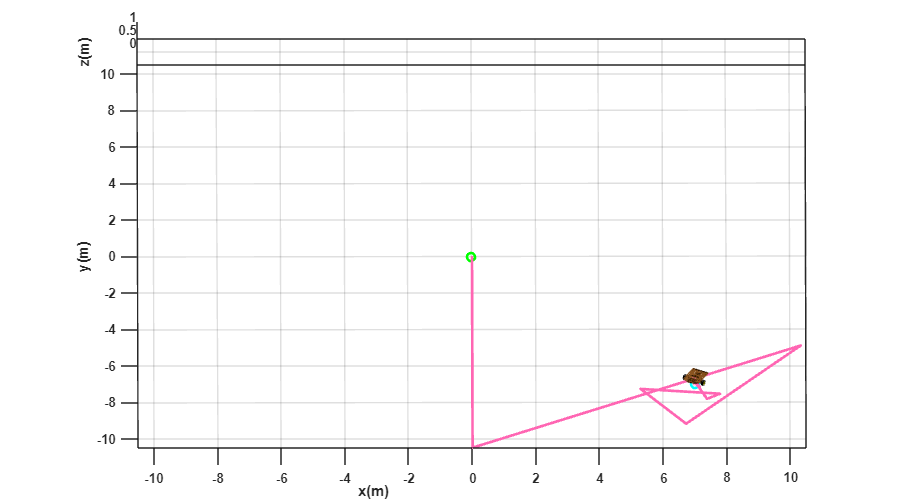

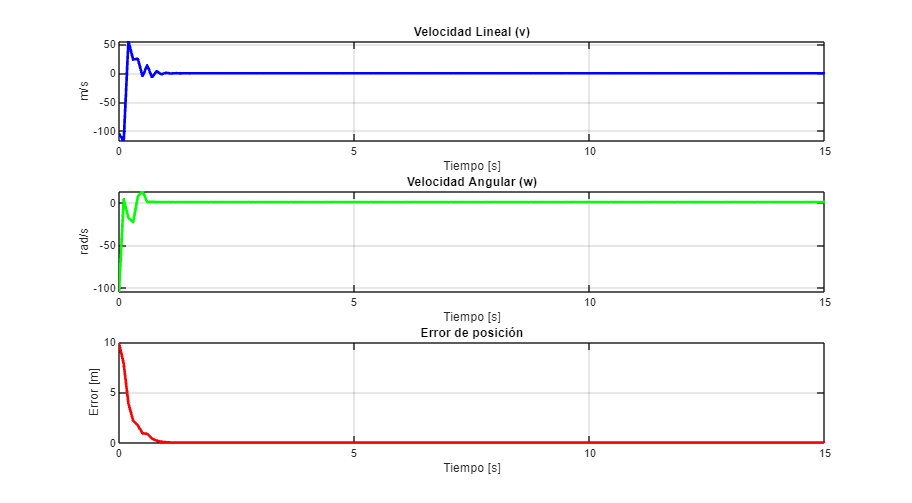

Inciso r)


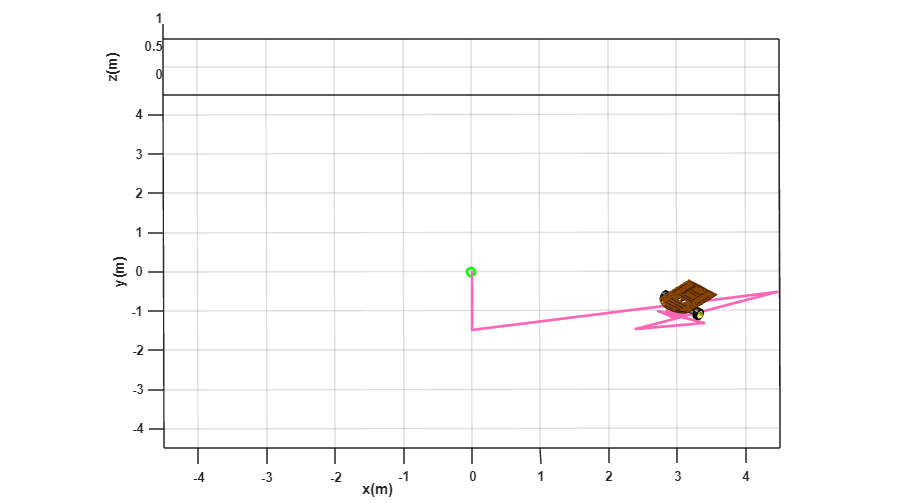

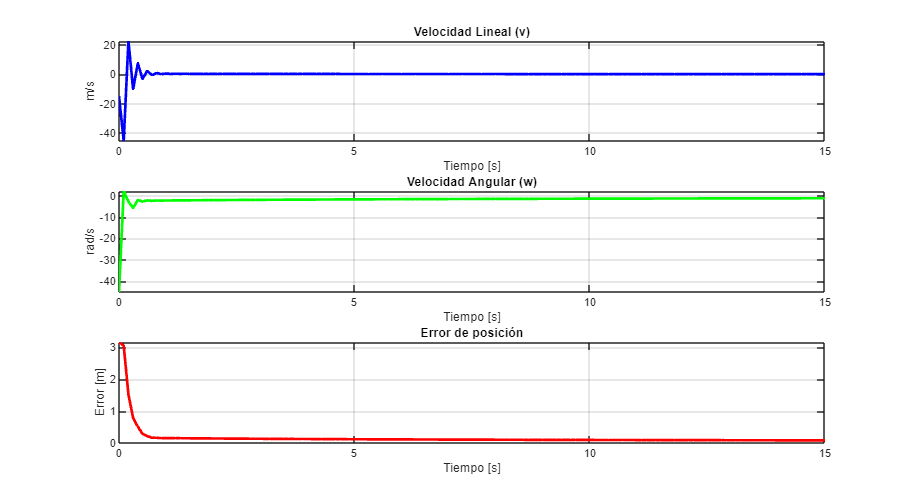

Inciso s)


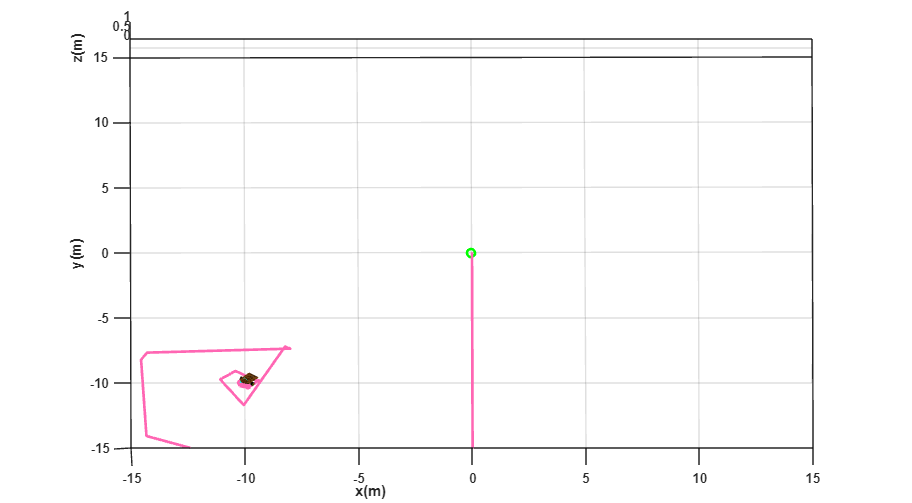

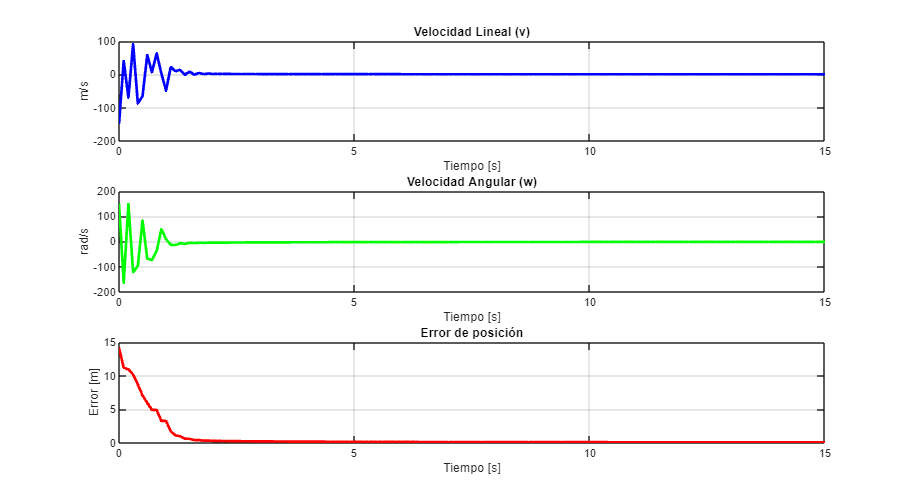

Inciso t)


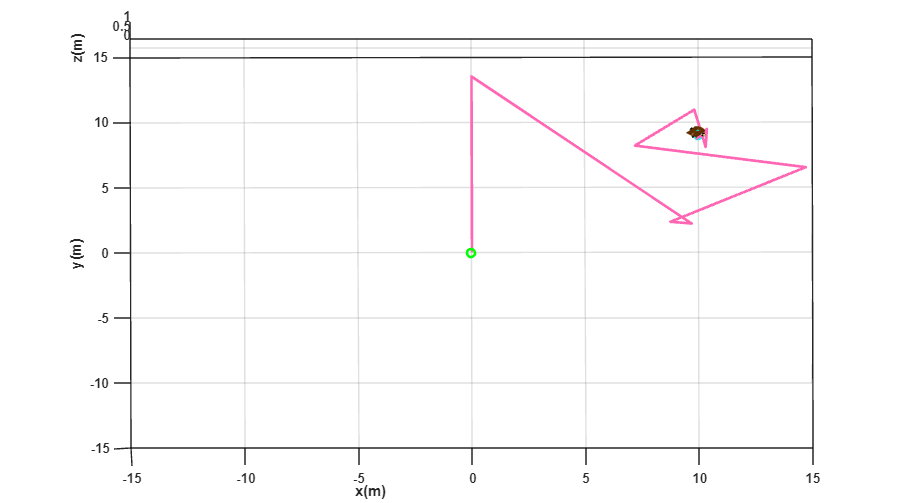

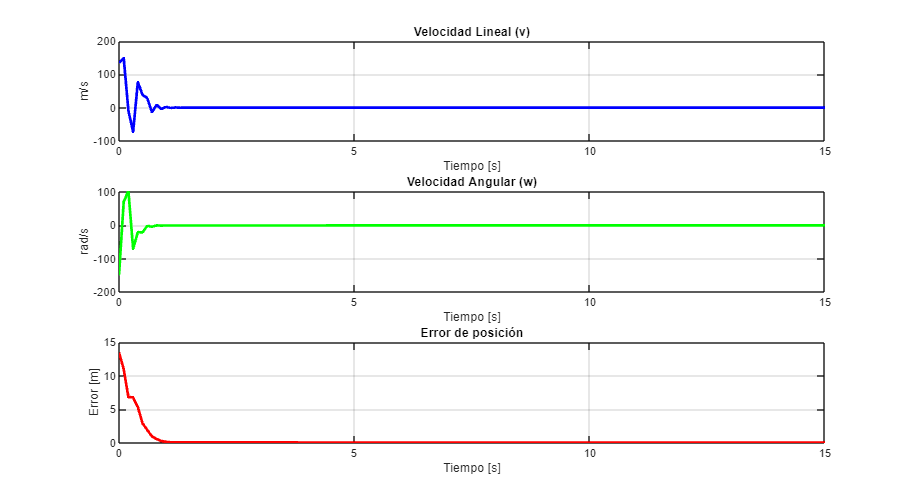

    graph = figure('Name',['Gráficas punto ' char(96+i)], 'position', sizeScreen);

    subplot(311)
    plot(t, v, 'b', 'LineWidth', 2); grid on;
    xlabel('Tiempo [s]'); ylabel('m/s');
    title('Velocidad Lineal (v)');

    subplot(312)
    plot(t, w, 'g', 'LineWidth', 2); grid on;
    xlabel('Tiempo [s]'); ylabel('rad/s');
    title('Velocidad Angular (w)');

    subplot(313)
    plot(t, Error, 'r', 'LineWidth', 2); grid on;
    xlabel('Tiempo [s]'); ylabel('Error [m]');
    title('Error de posición');
    
    pause(1); % Espera entre puntos
end